첫번째 cycle의 충전전류를 얻는다.

%load ryan3_gen_data.mat

idx = 1; % idxAll; 

battery_dataset(idx).Ic

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002   

battery_dataset(idx).Ic(1,:)

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


% 열벡터로 바꾼다.
Ic1 = battery_dataset(idx).Ic(1,:)'

Ic1 =          0
    4.3998
    4.4002
    4.4002
    4.4003
    4.3998
    4.3999
    4.4003
    4.4001
    4.4003


cycle_div = 50;
chargeCurrentIndex = linspace(0,1.2,100)

chargeCurrentIndex =          0    0.0121    0.0242    0.0364    0.0485    0.0606    0.0727    0.0848    0.0970    0.1091    0.1212    0.1333    0.1455    0.1576    0.1697    0.1818    0.1939    0.2061    0.2182    0.2303    0.2424    0.2545    0.2667    0.2788    0.2909    0.3030    0.3152    0.3273    0.3394    0.3515    0.3636    0.3758    0.3879    0.4000    0.4121    0.4242    0.4364    0.4485    0.4606    0.4727    0.4848    0.4970    0.5091    0.5212    0.5333    0.5455    0.5576    0.5697    0.5818    0.5939


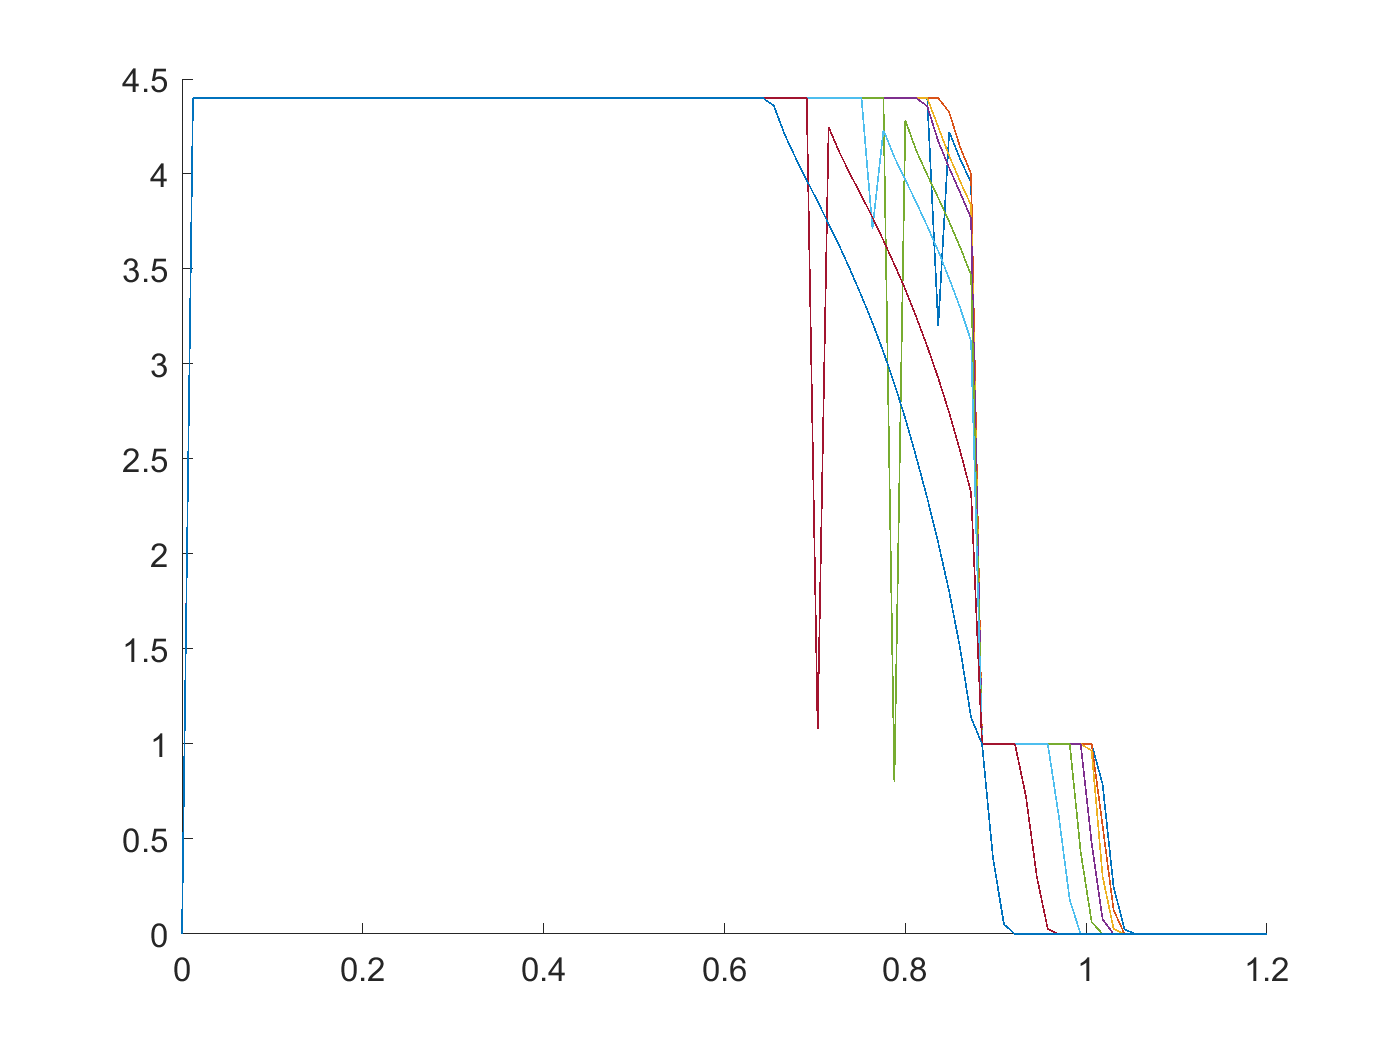

figure, hold on
for i = 1 : length(battery_dataset(1).Ic)
    if rem(i,cycle_div) == 0
    plot(chargeCurrentIndex,battery_dataset(1).Ic(i,:))
    end 
end
hold off

% 전체 데이타에 대해서 
IcFirst = zeros()

IcFirst = 0

IcFirst = battery_dataset(1).Ic(1,:)

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


%IcFirst = battery_dataset(2).Ic(1,:)
for i=1:length(battery_dataset)
    IcFirst(i,:) = battery_dataset(i).Ic(1,:);
end
IcFirst

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.800

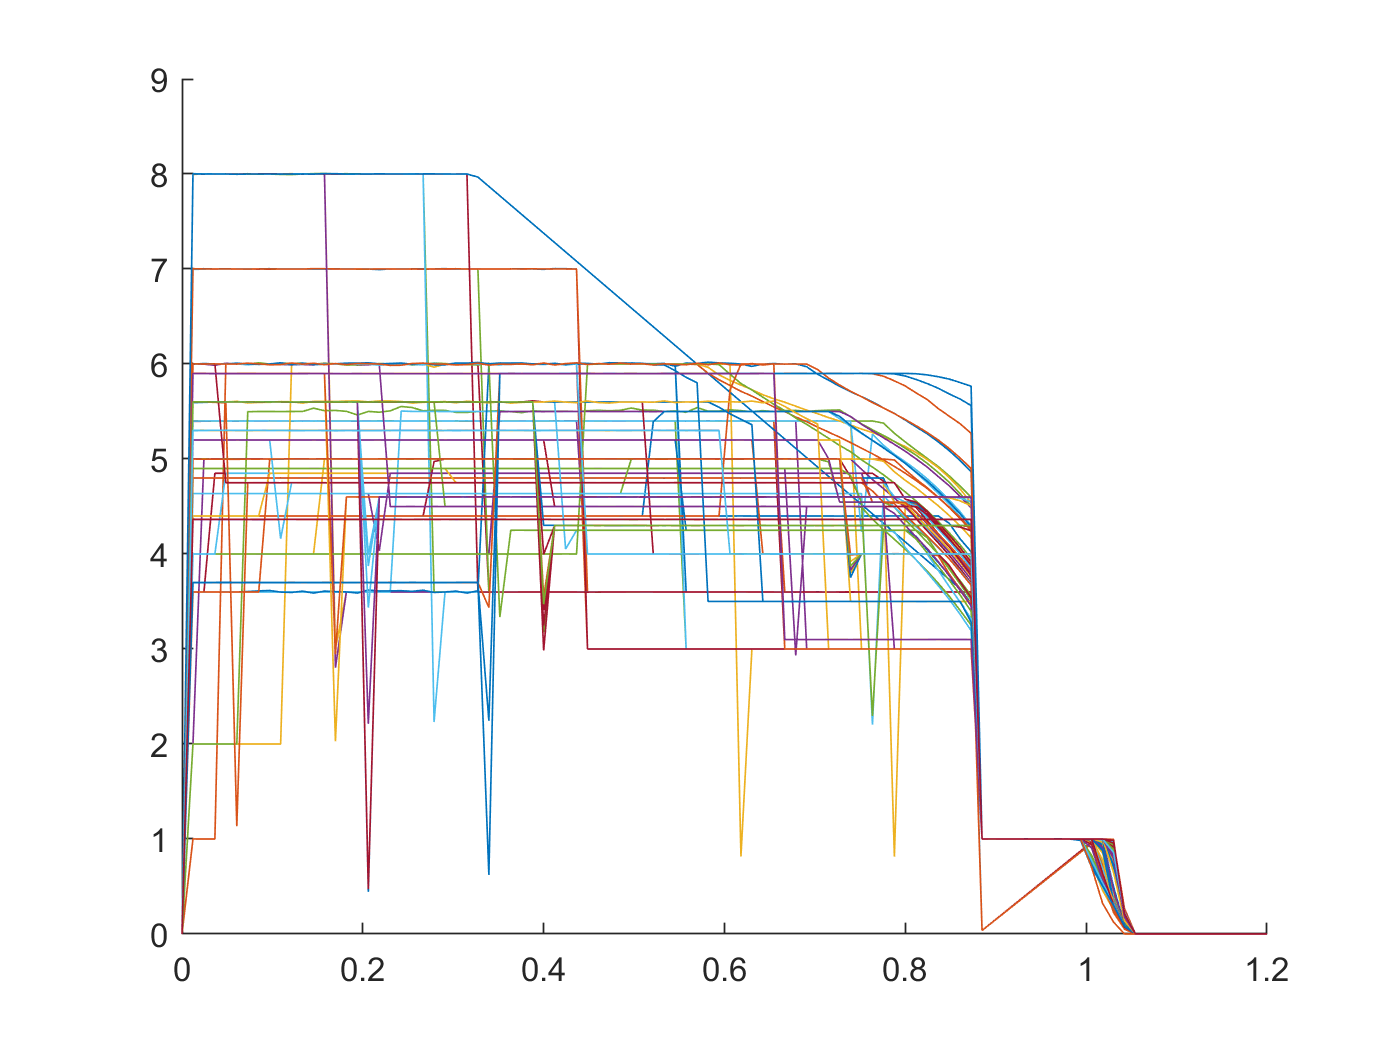

figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,IcFirst(i,:)) % movmean
    %end 
end
hold off

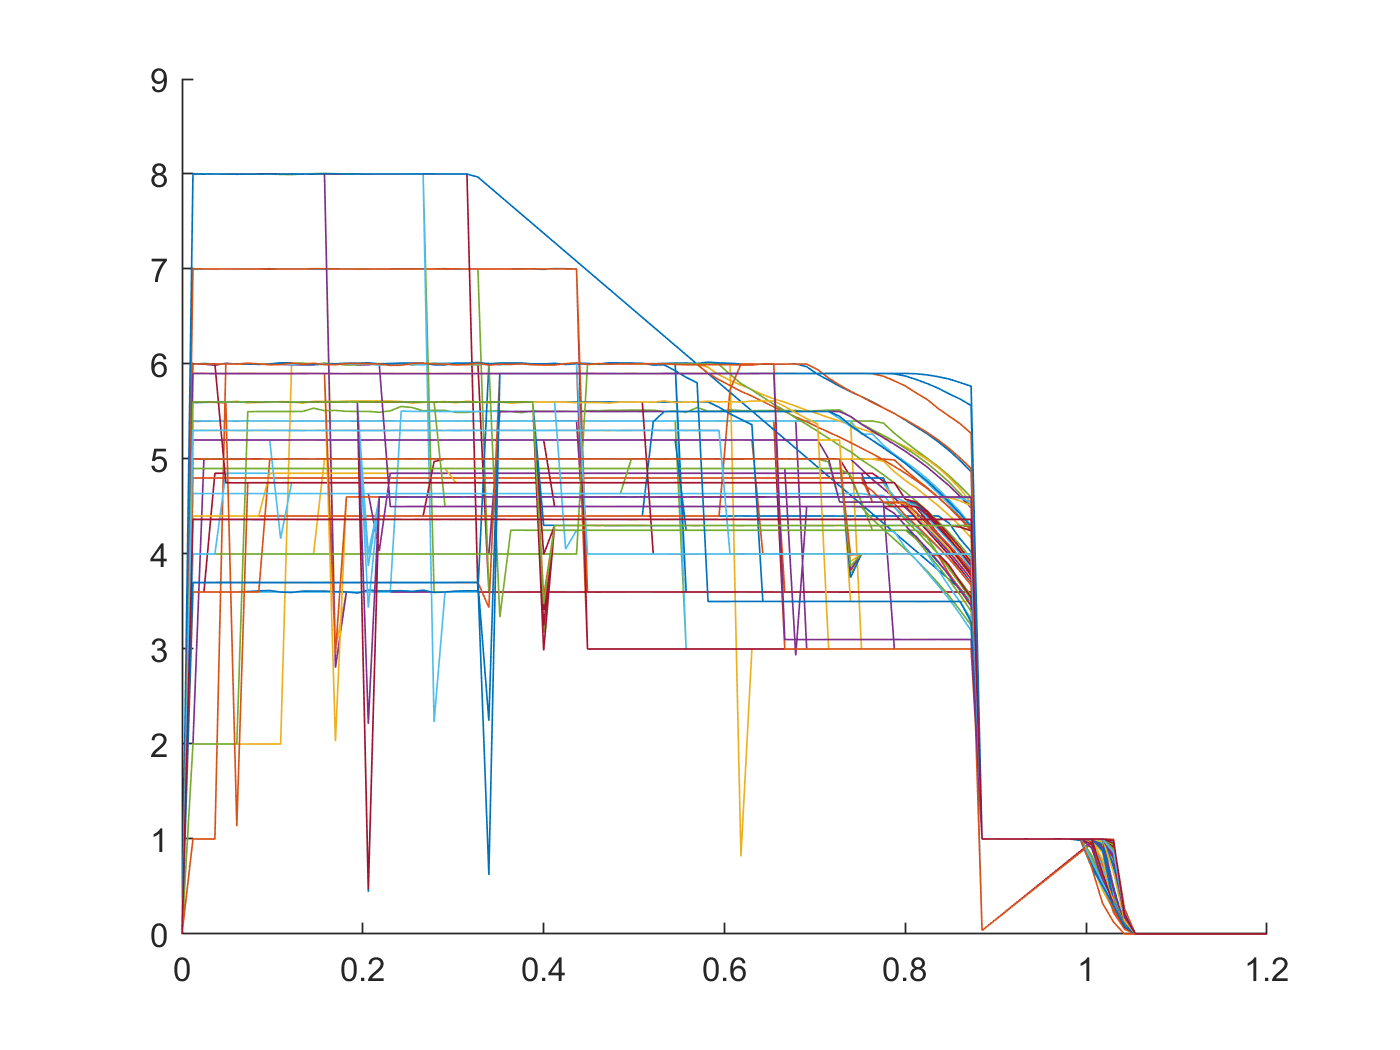

figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,filloutliers(IcFirst(i,:),'nearest','movmedian',3)) % movmean
    %end 
end
hold off

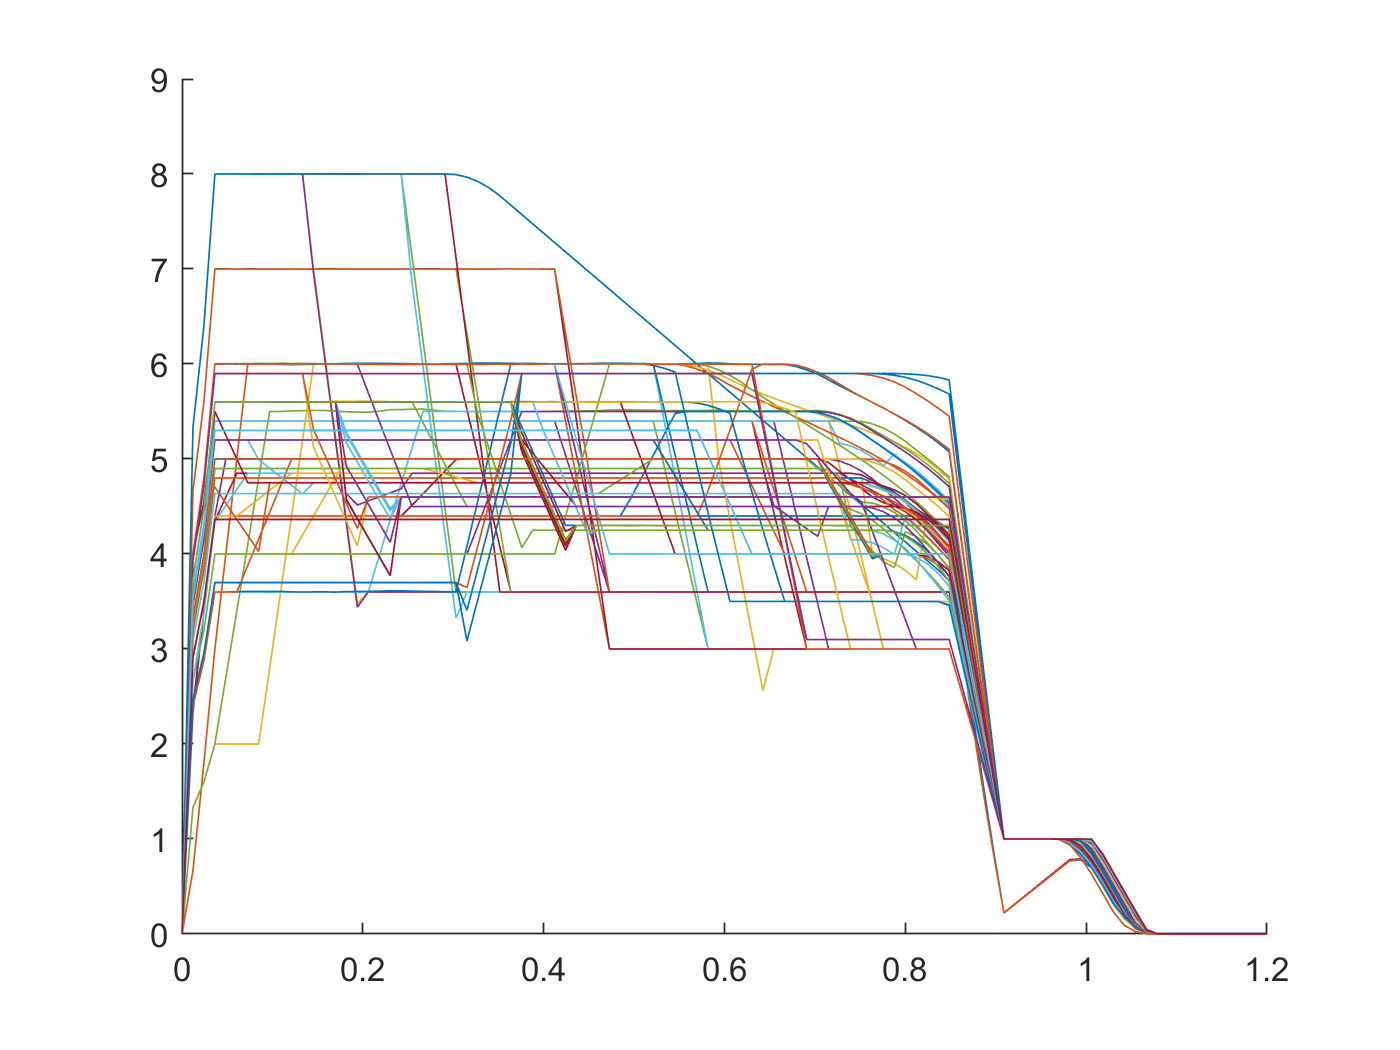


figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,smooth(IcFirst(i,:))) % movmean
    %end 
end
hold off


%IcFirst = IcFirst'
idx=idxAll;
cycleLife = [battery_dataset(idx).cycle_life ]'

cycleLife =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x = IcFirst

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

y = cycleLife

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);



IcFirst

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.800

% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


IcFirstSmall = blockproc(IcFirst, blockSize, meanFilterFunction)

IcFirstSmall =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.8400    4.8001    4.8000    4.8000    4.7999    4.8000    4.8000    4.8001    4.8000    4.8001    4.8000    4.8001    4.8000    4.4582    2.8282    1.0001    0.9867    0.0870         0         0
    3.8400    4.8000    4.7999    4.8000    4.8000    4.8000    4.8000    4.8000    4.8001    4.8000    4.7999    4.7999    4.7999    3.7292    2.8255    0.9999    0.9703    0.0923         0         0
    4.3201    5.3998    5.3999    5.3997    5.4000    5.4000    5.3997    4.3200    3.6001    3.6001    3.6000    3.6001    3.6000    3.6001    2.5600    1.0000    0.9999    0.1030         0         0
    4.3195    5.3999    5.3999    5.4003    5.3998    5.4005    5.4000    5.4000    5.4002    3.4801    2.9999    2.9999    3.0000    3.0000    2.2000    1.0001    1.0000    0.0783 

check1 = 0	+ 4.39981019088461 + 	4.40021996012301	+  4.40016441450076 +	4.40028052631599

check1 = 17.6005

check1 = check1 /5 

check1 = 3.5201


check2 = 0	+ 4.79984935638003	+ 4.80010278673953	+ 4.80019086870934	+ 4.80000036603629

check2 = 19.2001

check2 = check2 /5 

check2 = 3.8400



[rows, columns] = size(IcFirstSmall)

rows = 119

columns = 20



min(y)

ans = 109

max(y)

ans = 1171


yrate =  max(y) - min(y)

yrate = 1062

ymin = min(y)

ymin = 109

ynorm = (y - ymin) / yrate

ynorm =     0.3004
    0.1130
    0.1356
    0.2156
    0.2891
    0.2090
    0.1591
    0.1186
    0.1648
    0.3324


yback = ynorm * yrate + ymin

yback = 	1.0e+03 *

    0.4280
    0.2290
    0.2530
    0.3380
    0.4160
    0.3310
    0.2780
    0.2350
    0.2840
    0.4620


y

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

min(min(x))

ans = 0

max(max(x))

ans = 8.0061

xrate =  max(max(x)) - min(min(x))

xrate = 8.0061

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5495    0.5497    0.5495    0.5495    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5496    0.5497    0.5496
         0    0.5995    0.5996    0.5996    0.5995    0.5996    0.5995    0.5995    0.5996    0.5996    0.5995    0.5995    0.5996    0.5995    0.5995    0.5996    0.5995    0.5996    0.5995    0.5995    0.5995    0.5995    0.5995    0.5996    0.5995    0.5995    0.5995    0.5996    0.5996    0.5995    0.5996    0.5996    0.5995    0.5995    0.5995    0.5995    0.5996    0.5995    0.5996    0.5996    0.5995    0.5995    0.5995    0.5996    0.5996    0.5996    0.5996    0.5996    0.5995 

xback = xnorm * xrate + xmin

xback =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001 

x

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

%{
%cycle = cycle -1;
%cycle_data = [cycle key policy policy_readable];
cycle_data = [cycle key policy_str policy_readable_str];
cycleTable1 = array2table(cycle_data,...
    'VariableNames',{'cycle','key','policy','policy_readable'})
cycleTable = table(cycle, key, policy_str, policy_readable_str,Ic)
cycleTableSort = sortrows(cycleTable,1,'descend')
%}

#### 전류 패턴에 따른 라이프 사이클 예측 ..

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

x_trainValid = xnorm([idxTrain ],:)

x_trainValid =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351
         0    0.7490    0.7501    0.7494    0.7494    0.7505    0.7496    0.7489    0.7494    0.7510    0.7487    0.7506    0.7487    0.7490    0.7497    0.7505    0.7506    0.7510    0.7496    0.7501    0.7507    0.7491    0.7507    0.7483    0.7483    0.7507    0.7506    0.7514    0.7497    0.7507    0.7506    0.7507    0.7494    0.7495    0.7503    0.7488    0.7507    0.7501    0.7494    0.7511    0.7508    0.7506    0.7504    0.7481    0.7483    0.7406    0.7319    0.7248    

x_test = xnorm([idxTest idxValid],:)

x_test =          0    0.7493    0.7493    0.7494    0.7497    0.7496    0.7484    0.7494    0.7488    0.7493    0.7487    0.7489    0.7499    0.7494    0.7494    0.7493    0.7492    0.7492    0.7479    0.7488    0.7488    0.7488    0.7483    0.7503    0.7490    0.7506    0.7495    0.7494    0.7492    0.7481    0.7508    0.7509    0.7491    0.7488    0.7498    0.7480    0.7495    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4997    0.4997    0.4996    0.4996    0.4996
         0    0.4996    0.4996    0.4996    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058


y_trainValid = ynorm([idxTrain ])

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test = ynorm([idxTest idxValid])

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



mdl = fitlm(x_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                   Estimate       SE         tStat      pValue
                   _________    _______    _________    ______

    (Intercept)       222.16      349.1      0.63638     NaN  


coeff = mdl.Coefficients.Estimate

coeff = 	1.0e+03 *

    0.2222
         0
    0.0012
    0.0039
   -0.0122
   -0.2051
   -0.0492
    0.1761
    0.0828
    0.3412


x_trainValid(1,:)

ans =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:101)+coeff(1)

yhat =     0.0000
    0.0055
    0.0084
    0.0188
    0.0342
    0.0339
    0.0406
    0.0244
    0.0408
    0.0243


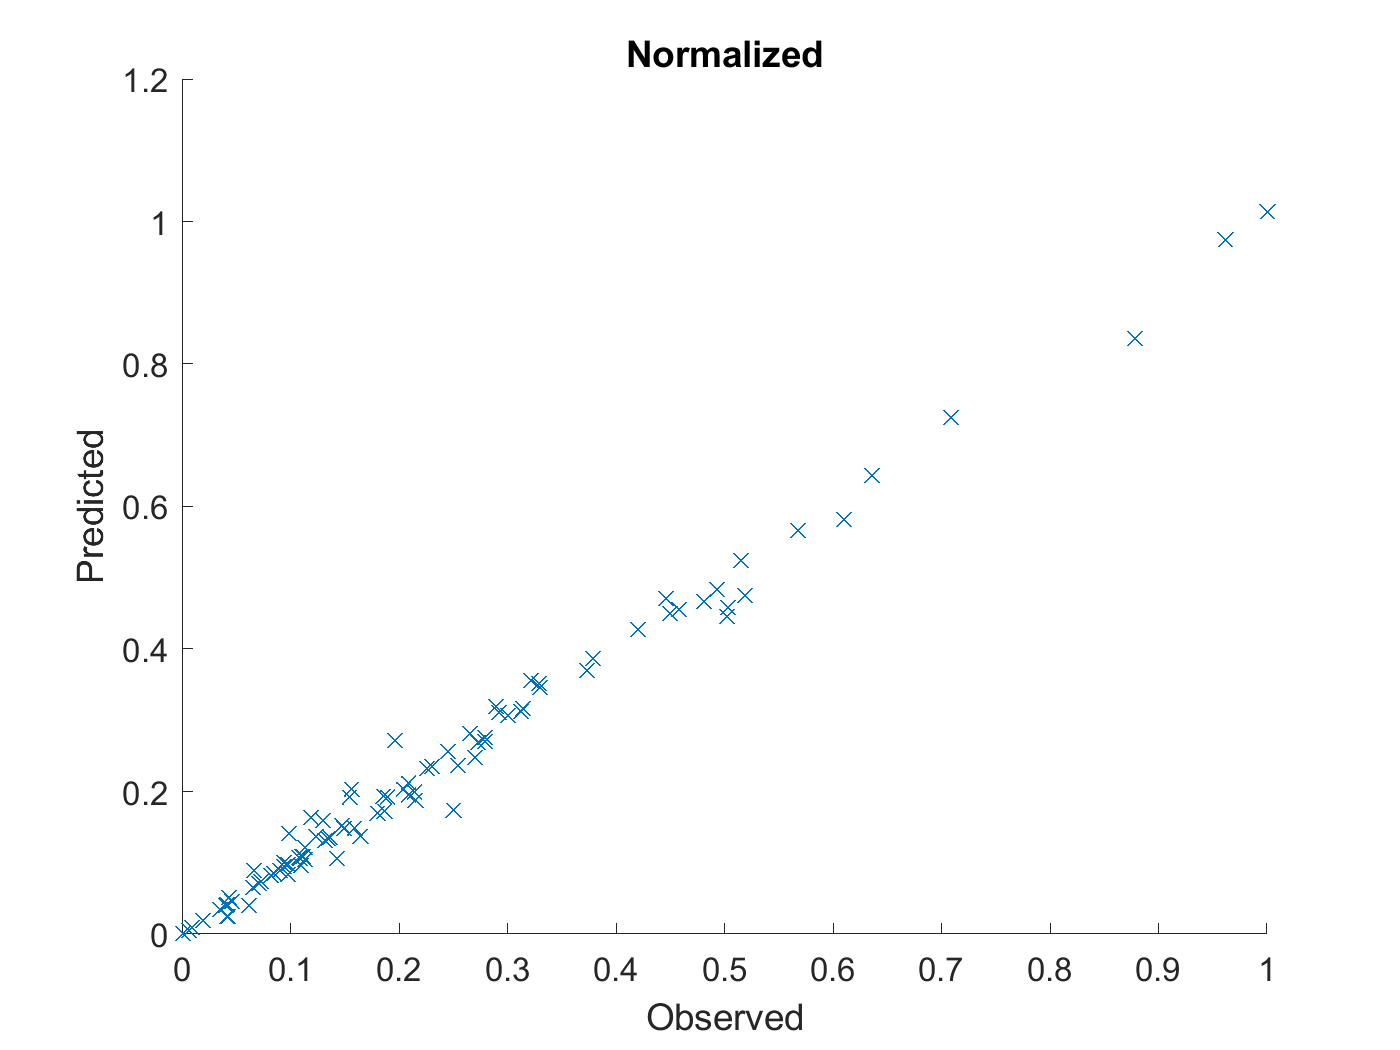

figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

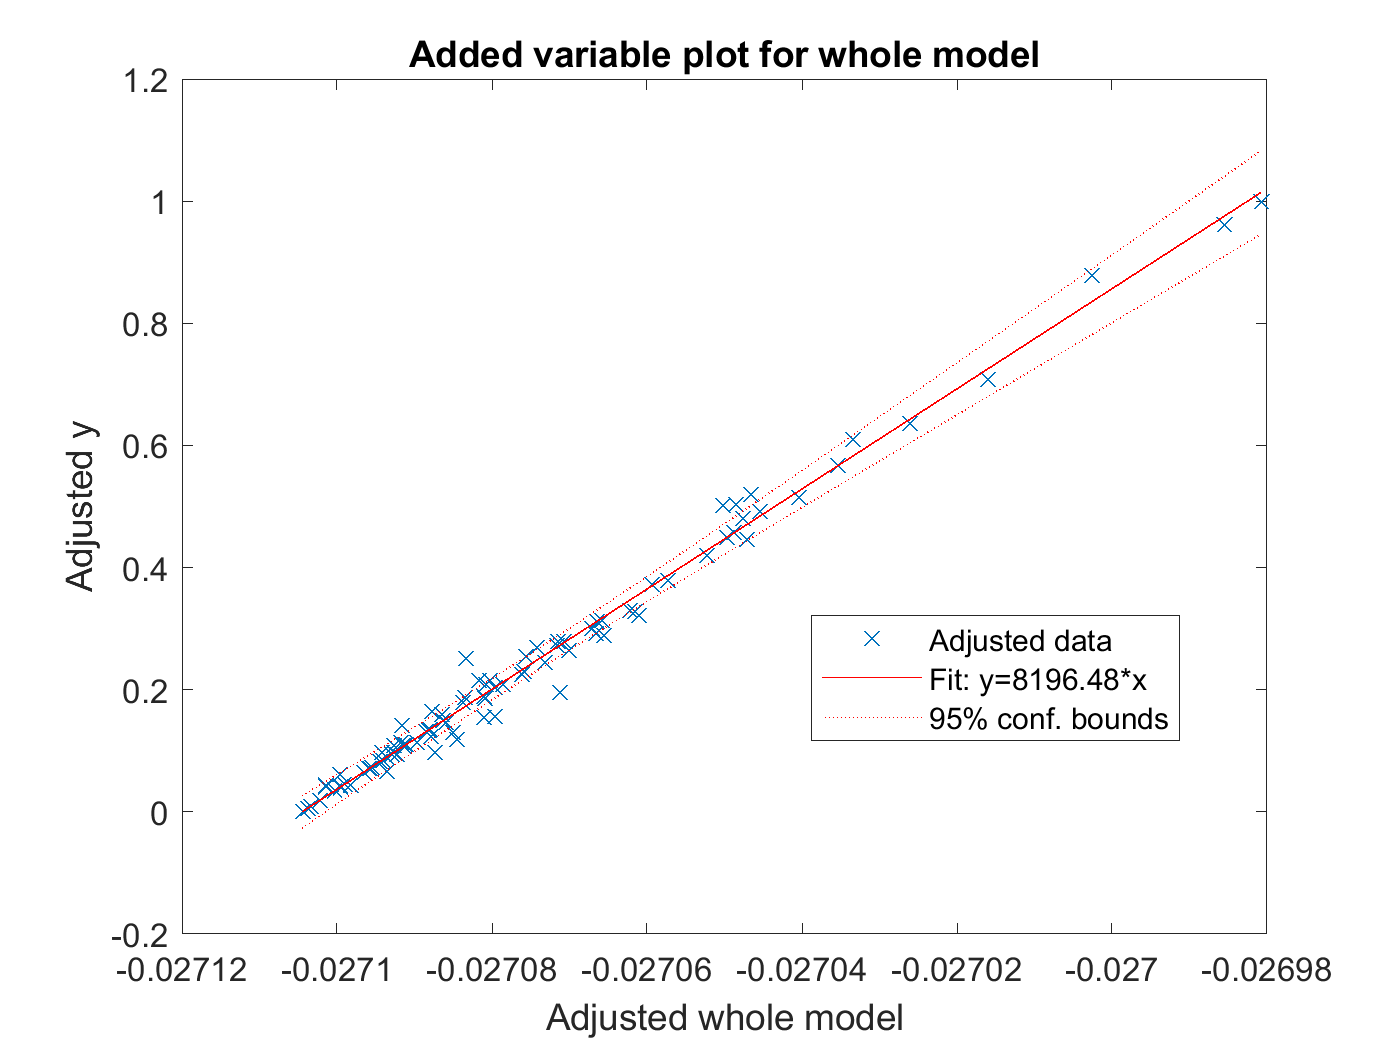


%capHat = Ic(1)

plot(mdl)

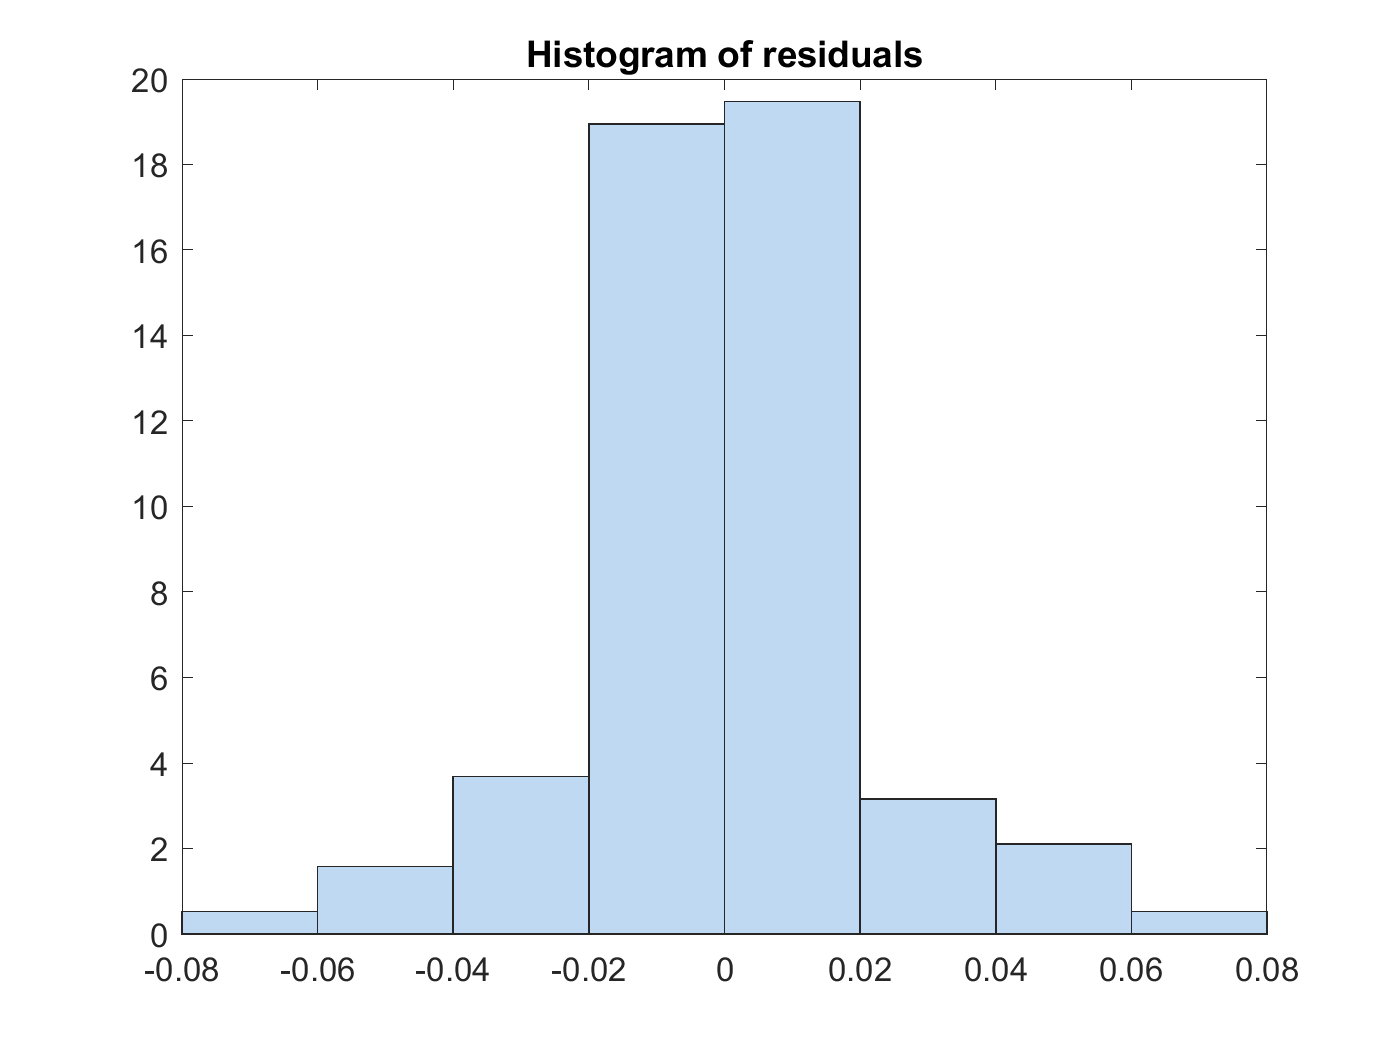

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,x_trainValid)

yfit =     0.0000
    0.0055
    0.0084
    0.0188
    0.0342
    0.0339
    0.0406
    0.0244
    0.0408
    0.0243


yfit_test = predict(mdl,x_test)

yfit_test =     0.0854
    1.2810
   45.3252
    0.0211
    0.3347
    3.4721
    0.2262
    0.4617
    0.1376
    0.4139




y= y_trainValid

y =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



% denormalize
yfit = yfit * yrate + ymin;
y = y * yrate + ymin;
yfit_test = yfit_test * yrate + ymin;
y_test = y_test * yrate + ymin;


MAE = mean(abs(yfit-y))

MAE = 14.1852

adjMAE = MAE/range(y)

adjMAE = 0.0134

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1150
    0.1180
    0.1290
    0.1460
    0.1460
    0.1520
    0.1530
    0.1530
    0.1540


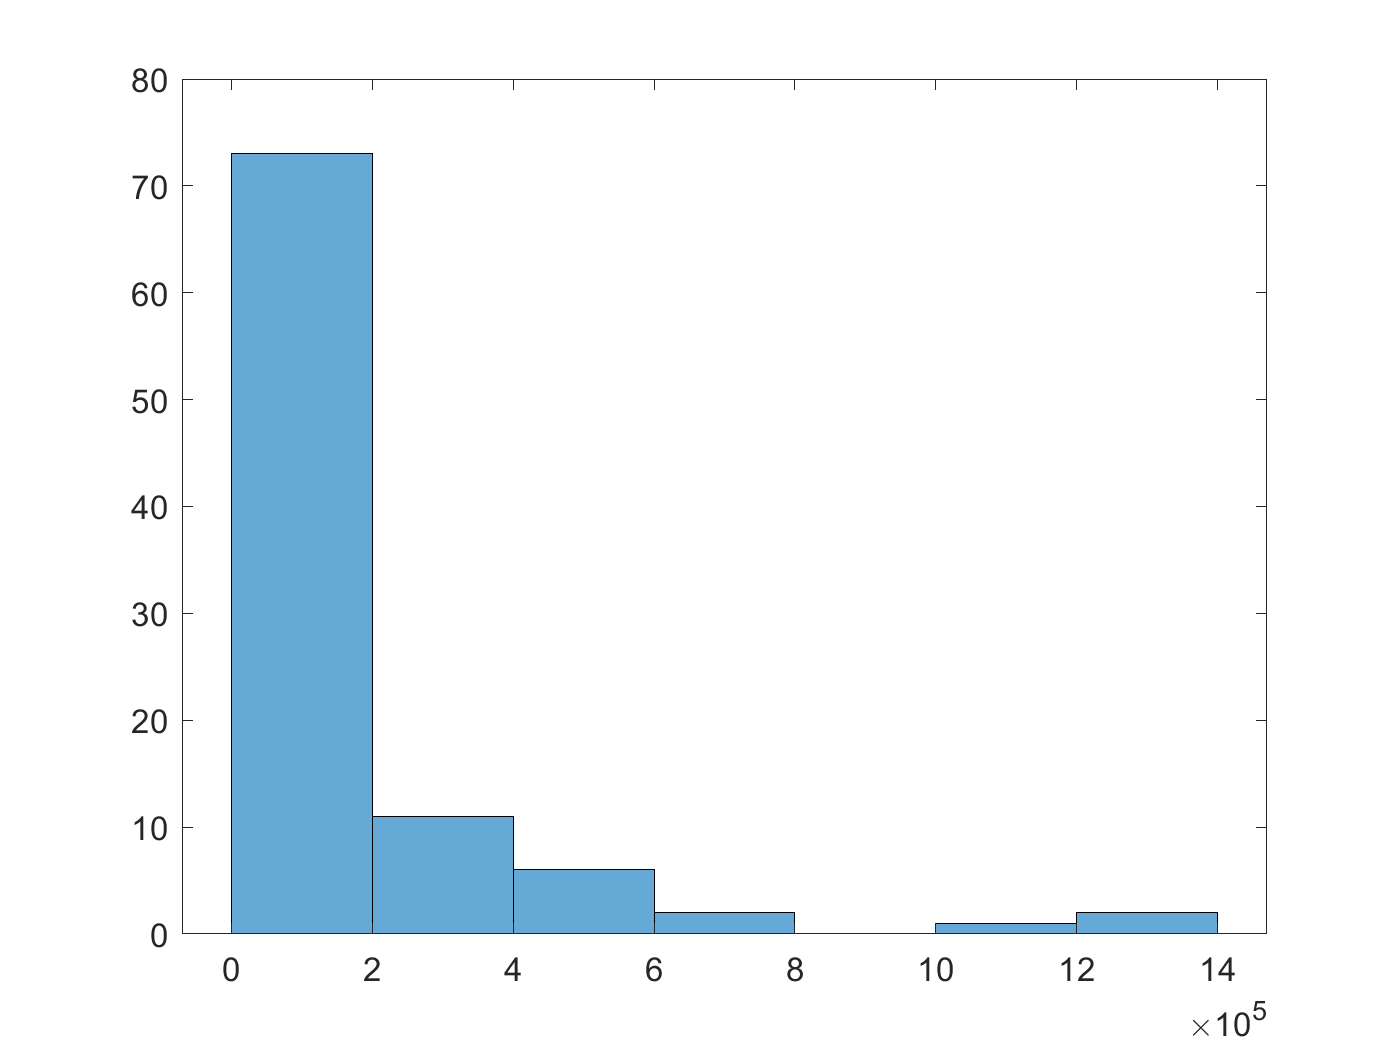

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 418.1211

(y_test - yfit_test) 

ans = 	1.0e+05 *

   -0.0006
   -0.0130
   -0.4804
    0.0009
   -0.0023
   -0.0353
   -0.0003
   -0.0024
    0.0016
   -0.0004


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 3.4354e+04

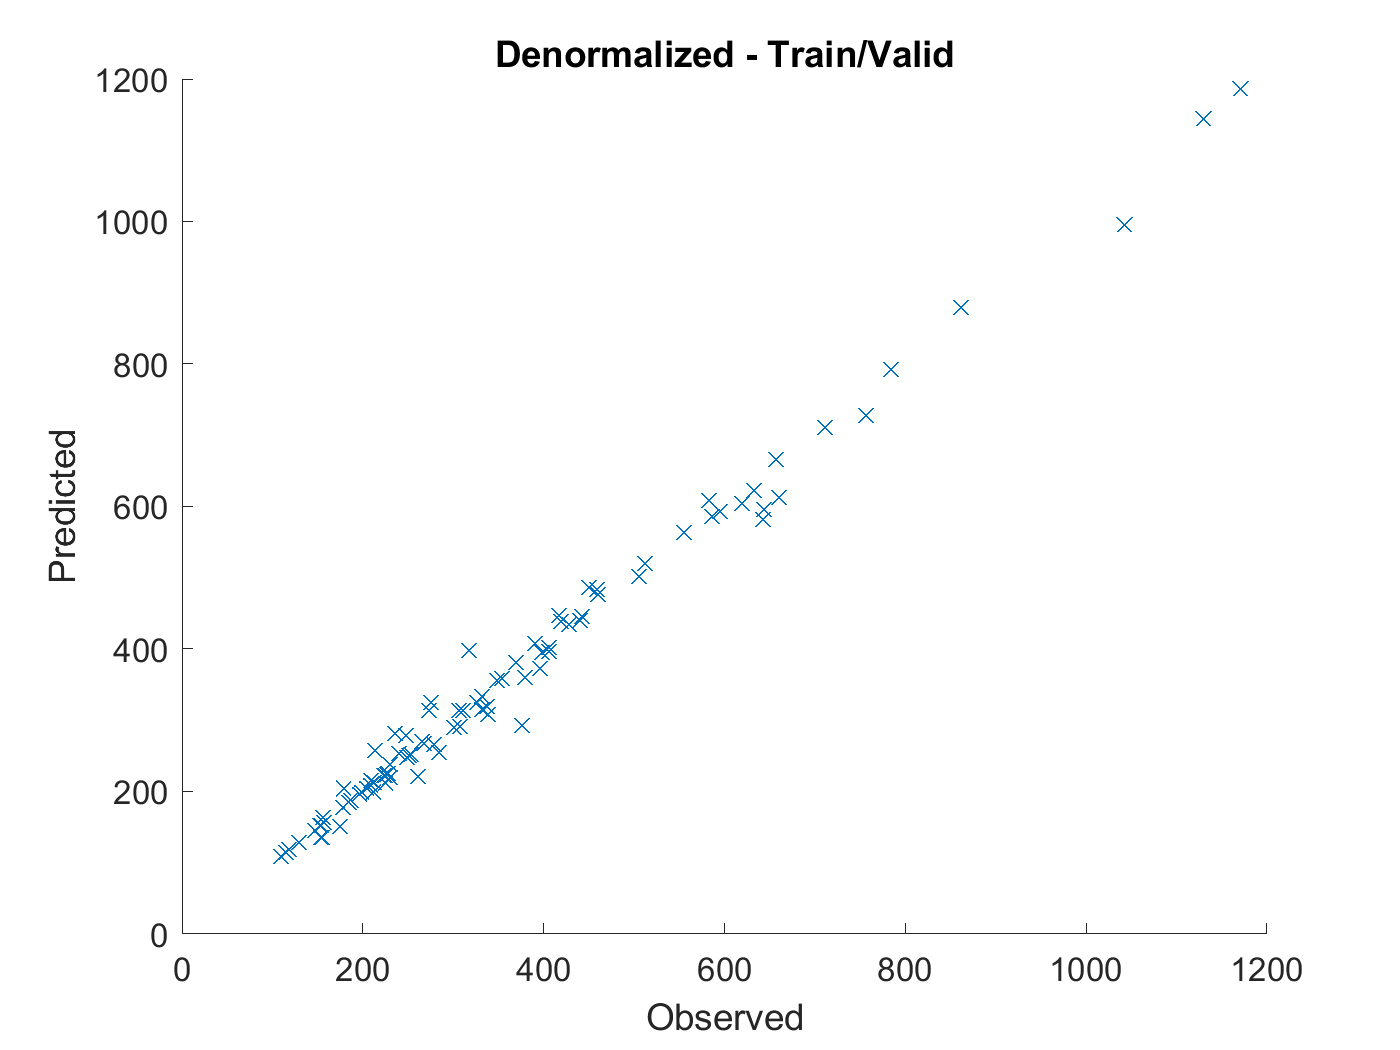


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

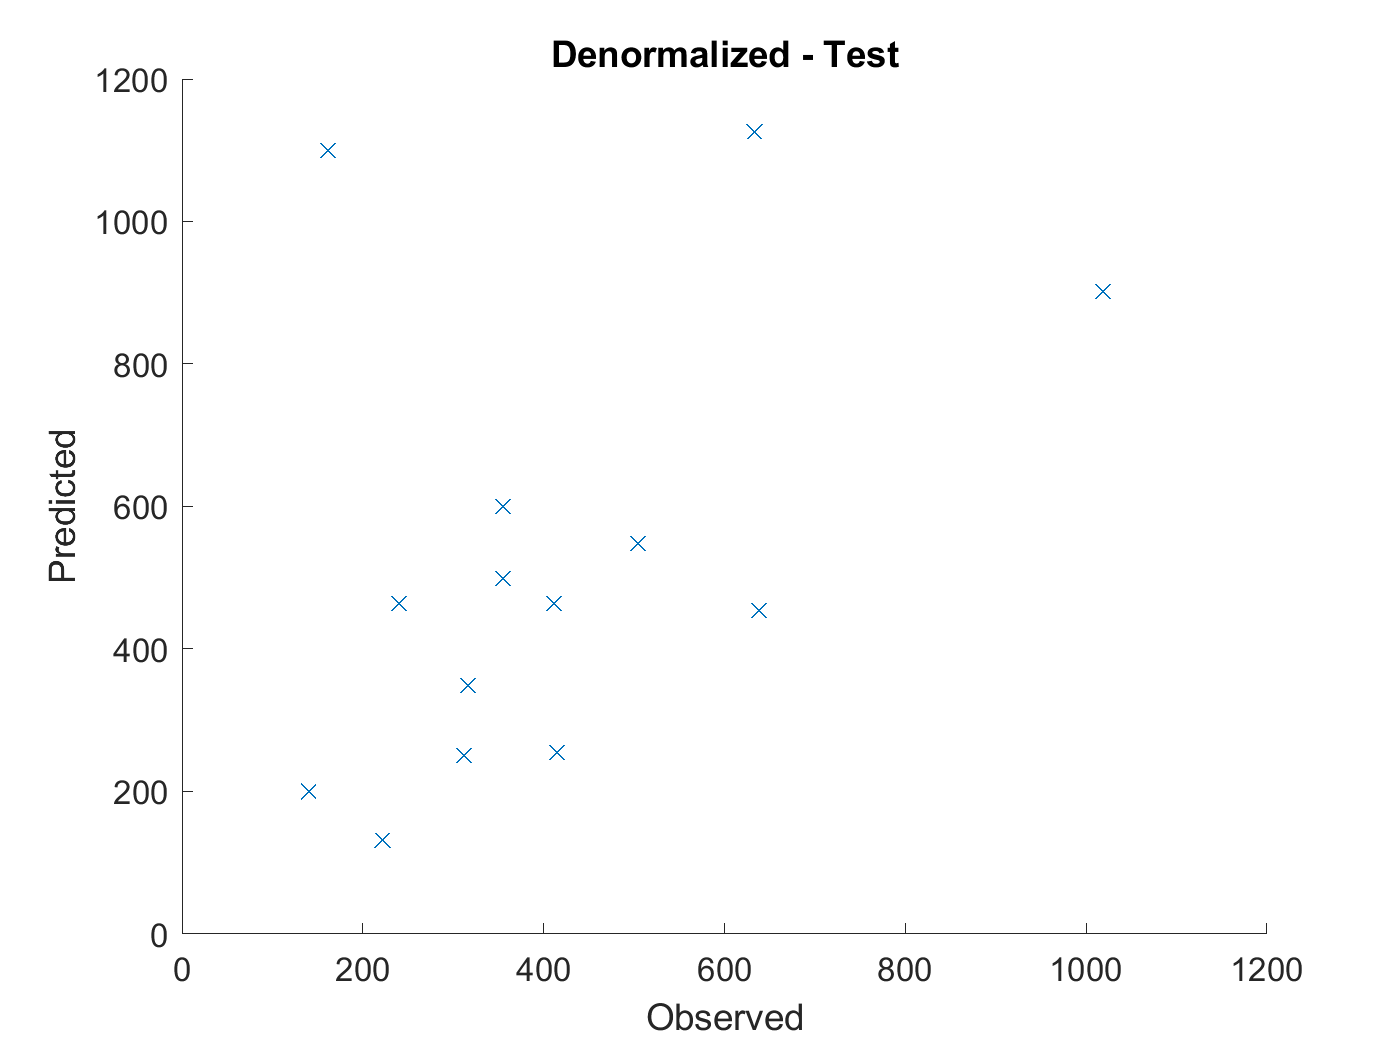


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'
xlim([0 1200]), ylim([0 1200])


% 테스트 셋에서는 예측이 전혀 안된다.


#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

x = IcFirstSmall

x =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.8400    4.8001    4.8000    4.8000    4.7999    4.8000    4.8000    4.8001    4.8000    4.8001    4.8000    4.8001    4.8000    4.4582    2.8282    1.0001    0.9867    0.0870         0         0
    3.8400    4.8000    4.7999    4.8000    4.8000    4.8000    4.8000    4.8000    4.8001    4.8000    4.7999    4.7999    4.7999    3.7292    2.8255    0.9999    0.9703    0.0923         0         0
    4.3201    5.3998    5.3999    5.3997    5.4000    5.4000    5.3997    4.3200    3.6001    3.6001    3.6000    3.6001    3.6000    3.6001    2.5600    1.0000    0.9999    0.1030         0         0
    4.3195    5.3999    5.3999    5.4003    5.3998    5.4005    5.4000    5.4000    5.4002    3.4801    2.9999    2.9999    3.0000    3.0000    2.2000    1.0001    1.0000    0.0783         0  

y = cycleLife

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


[ynorm,xnorm] = minmax_norm_new_with_param(y,x,ymin,yrate,xmin,xrate);

x_trainValid = xnorm([idxTrain idxValid],:)

x_trainValid =     0.1998    0.2498    0.7494    0.7494    0.7485    0.7494    0.7494    0.7495    0.7494    0.7457    0.7156    0.6890    0.6641    0.6316    0.4004    0.1249    0.1050    0.0082         0         0
    0.5996    0.7499    0.7493    0.7504    0.7494    0.7506    0.7501    0.7500    0.7496    0.6143    0.4372    0.4372    0.4372    0.4372    0.3069    0.1249    0.1047    0.0096         0         0
    0.5593    0.6994    0.6995    0.6995    0.6995    0.6994    0.6994    0.6995    0.6995    0.6981    0.5809    0.4372    0.4372    0.4372    0.3075    0.1249    0.1061    0.0094         0         0
    0.5596    0.6995    0.6995    0.6995    0.6995    0.6994    0.6995    0.5259    0.5309    0.5308    0.5308    0.5308    0.5308    0.4923    0.3018    0.1249    0.1051    0.0092         0         0
    0.4896    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.5200    0.5226    0.3259    0.1249    0.1117    0.0095 

x_test = xnorm([idxTest],:)

x_test =     0.5995    0.7491    0.7493    0.7489    0.7490    0.7494    0.7499    0.5993    0.4996    0.4997    0.4996    0.4996    0.4996    0.4953    0.3115    0.1249    0.1078    0.0099         0         0
    0.4209    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.5906    0.5458    0.3370    0.1249    0.1144    0.0096         0         0
    0.5196    0.6236    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5569    0.3494    0.1249    0.1171    0.0098         0         0
    0.6995    0.8743    0.8743    0.8743    0.8743    0.8743    0.8744    0.5746    0.3747    0.3747    0.3747    0.3747    0.3747    0.3747    0.2748    0.1249    0.1228    0.0127         0         0
    0.6994    0.8742    0.8744    0.8743    0.8743    0.7045    0.4497    0.4497    0.4497    0.4497    0.4496    0.4497    0.4496    0.4497    0.3198    0.1249    0.1184    0.0111       


y_trainValid = ynorm([idxTrain idxValid])

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test = ynorm([idxTest])

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



mdl = fitlm(x_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      0.4149     0.5099     0.81369       0.41807
    x1             -0.21489    0.33095     -0.6493       0.51787
    x2              0.17704    0.39234     0.45124       0.65295
    x3             -0.50363    0.46835     -1.0753       0.28524
    x4              0.02596    0.52221    0.049712       0.96047
    x5              0.16015    0.76551      0.2092       0.83478
    x6             -0.36978    0.66408    -0.55


coeff = mdl.Coefficients.Estimate

coeff =     0.4149
   -0.2149
    0.1770
   -0.5036
    0.0260
    0.1601
   -0.3698
   -0.1214
    0.4558
   -0.2644


x_trainValid(1,:)

ans =     0.1998    0.2498    0.7494    0.7494    0.7485    0.7494    0.7494    0.7495    0.7494    0.7457    0.7156    0.6890    0.6641    0.6316    0.4004    0.1249    0.1050    0.0082         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:21)+coeff(1)

yhat =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


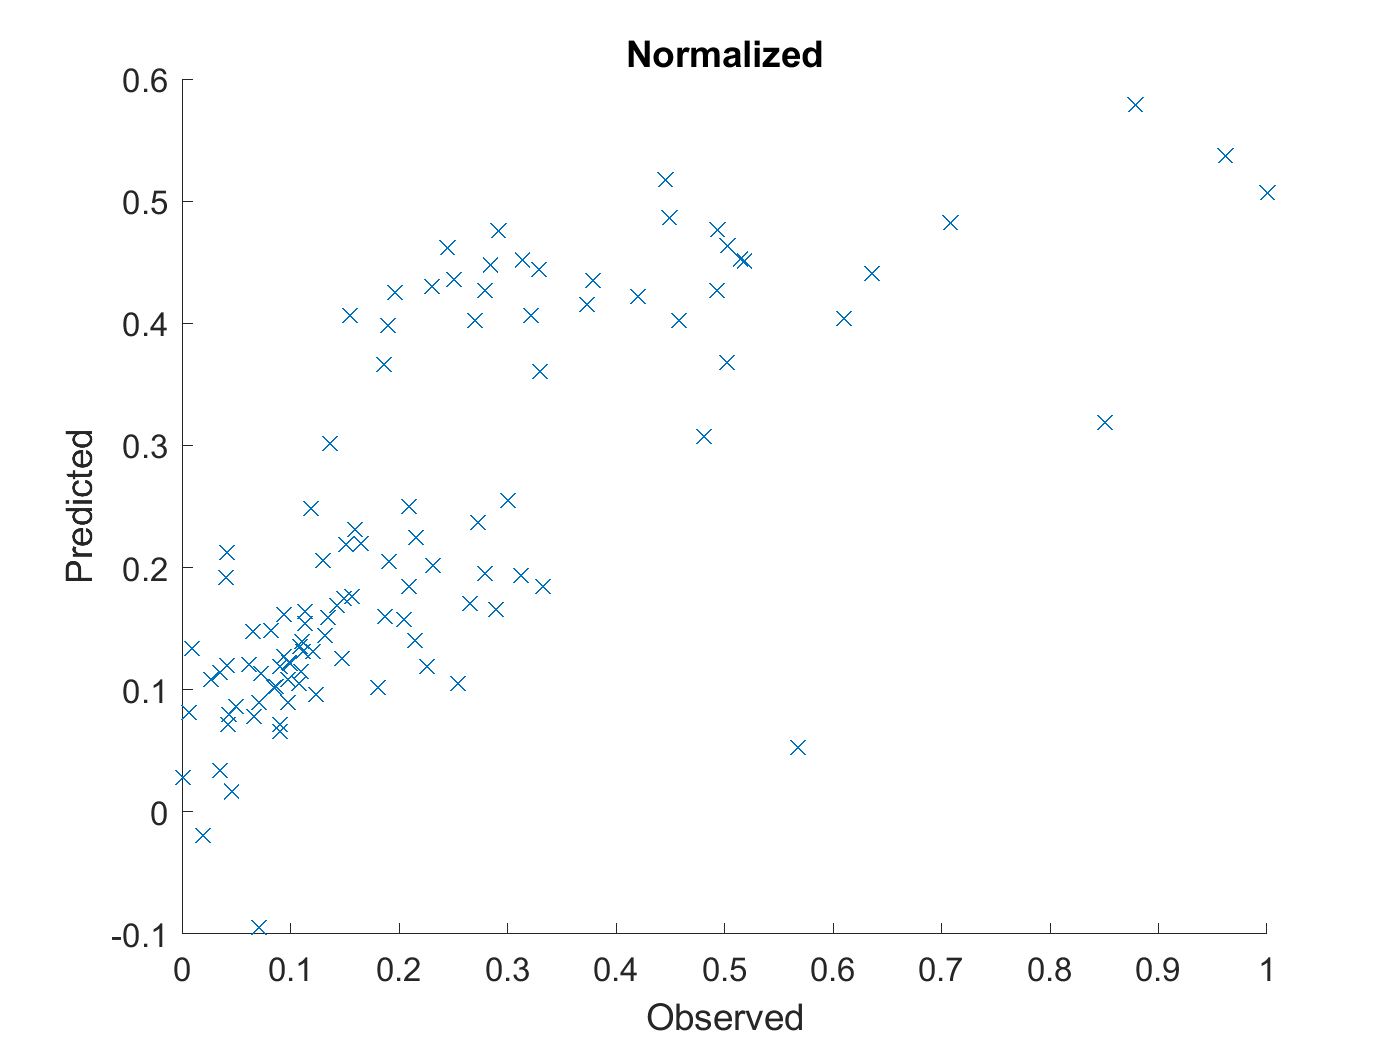

figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

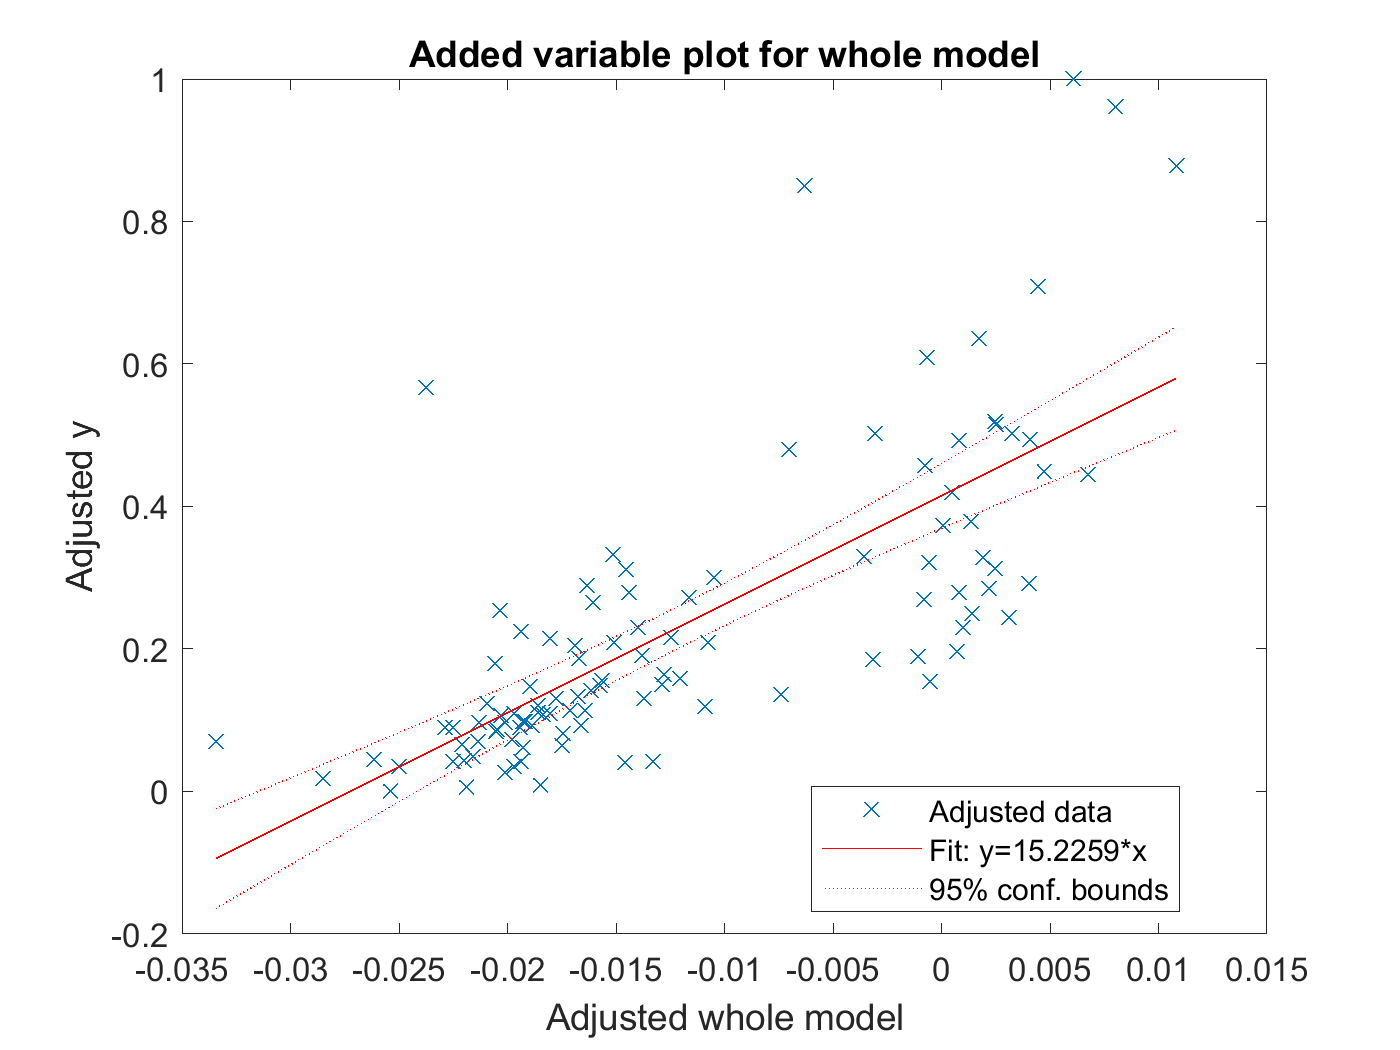


%capHat = Ic(1)

plot(mdl)

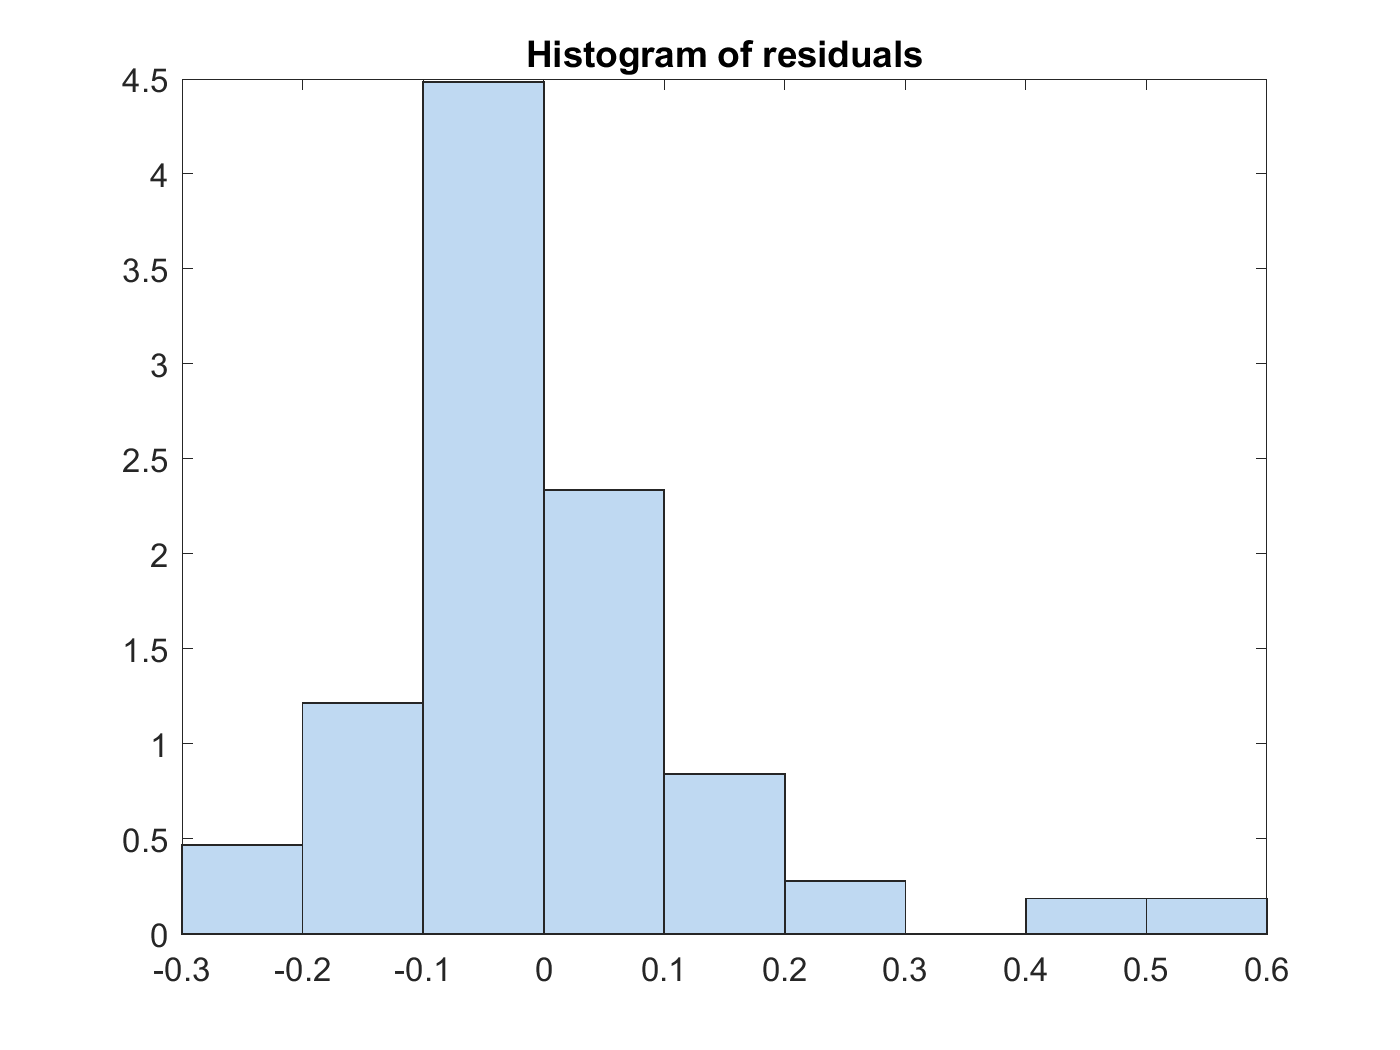

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,x_trainValid)

yfit =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


yfit_test = predict(mdl,x_test)

yfit_test =     0.0222
    0.1122
    0.1233
    0.0877
    0.1083
    0.1750
    0.1750
    0.4429
    0.3961
    0.5218




y= y_trainValid

y =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



% denormalize
yfit = yfit * yrate + ymin;
y = y * yrate + ymin;
yfit_test = yfit_test * yrate + ymin;
y_test = y_test * yrate + ymin;


MAE = mean(abs(yfit-y))

MAE = 99.5134

adjMAE = MAE/range(y)

adjMAE = 0.0937

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1149
    0.1179
    0.1290
    0.1459
    0.1460
    0.1518
    0.1528
    0.1529
    0.1539


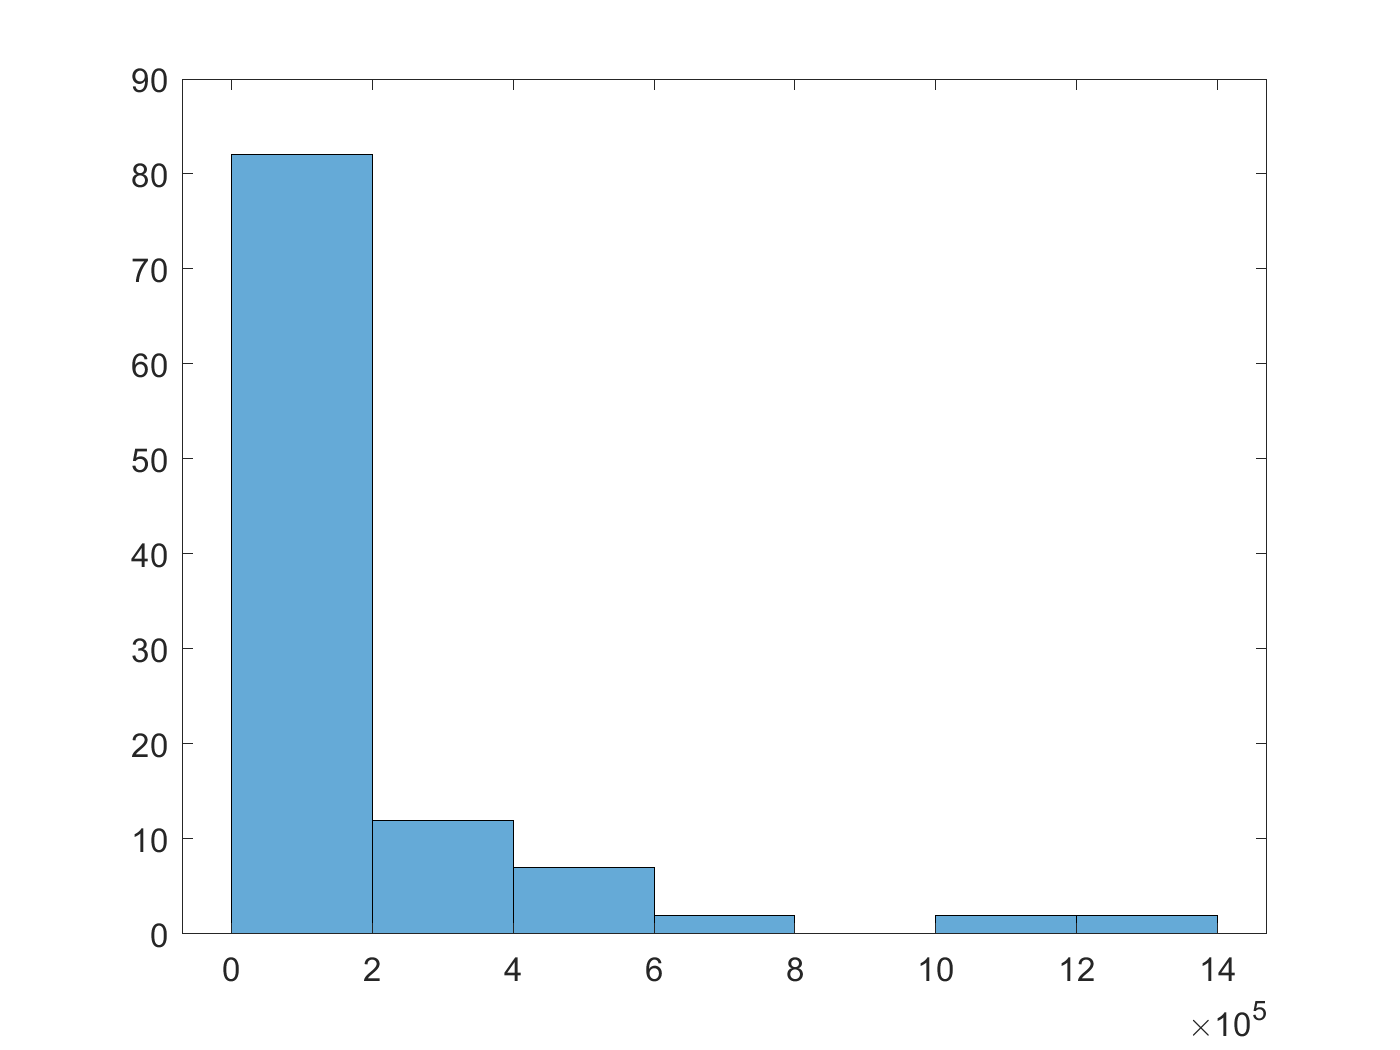

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 420.2800

(y_test - yfit_test) 

ans =     7.4567
  -60.1449
  -36.9517
   19.8146
   14.9991
  -24.8040
   21.1814
 -224.3624
 -115.6770
 -159.1358


%x_test = xnorm([idxTest],:)
y_test_diff = horzcat(y_test, (y_test - yfit_test))

y_test_diff = 	1.0e+03 *

    0.1400    0.0075
    0.1680   -0.0601
    0.2030   -0.0370
    0.2220    0.0198
    0.2390    0.0150
    0.2700   -0.0248
    0.3160    0.0212
    0.3550   -0.2244
    0.4140   -0.1157
    0.5040   -0.1591


y_test_diff_percentage = abs(y_test - yfit_test)./y_test

y_test_diff_percentage =     0.0533
    0.3580
    0.1820
    0.0893
    0.0628
    0.0919
    0.0670
    0.6320
    0.2794
    0.3157


y_test_diff_percentage_avg = sum(y_test_diff_percentage)/length(y_test_diff_percentage)

y_test_diff_percentage_avg = 0.2260


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 136.1904

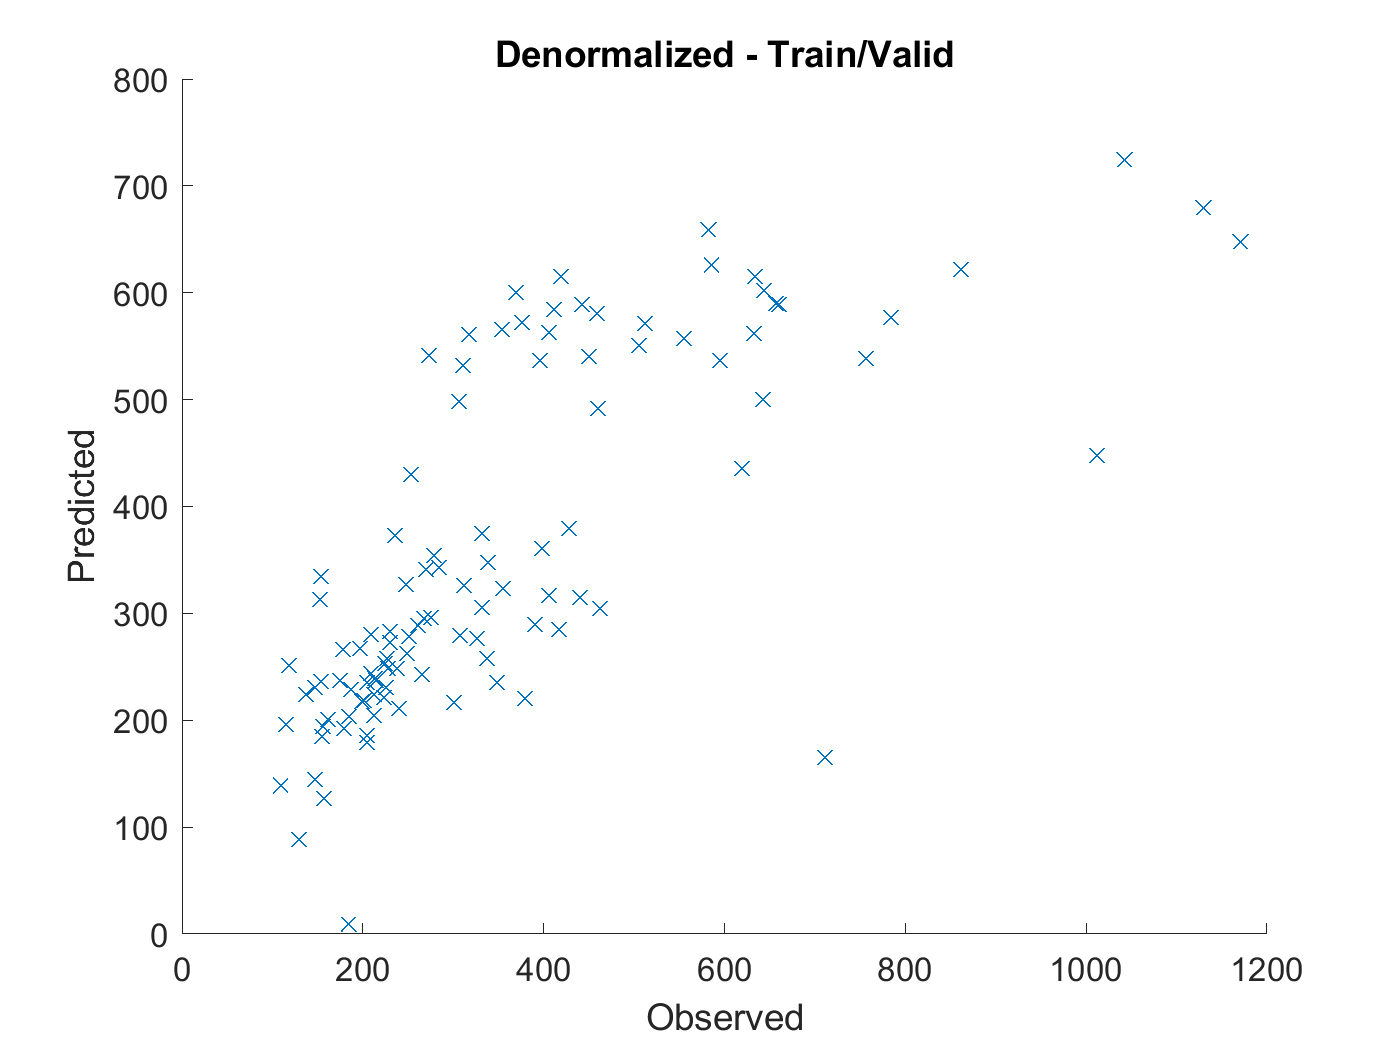


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

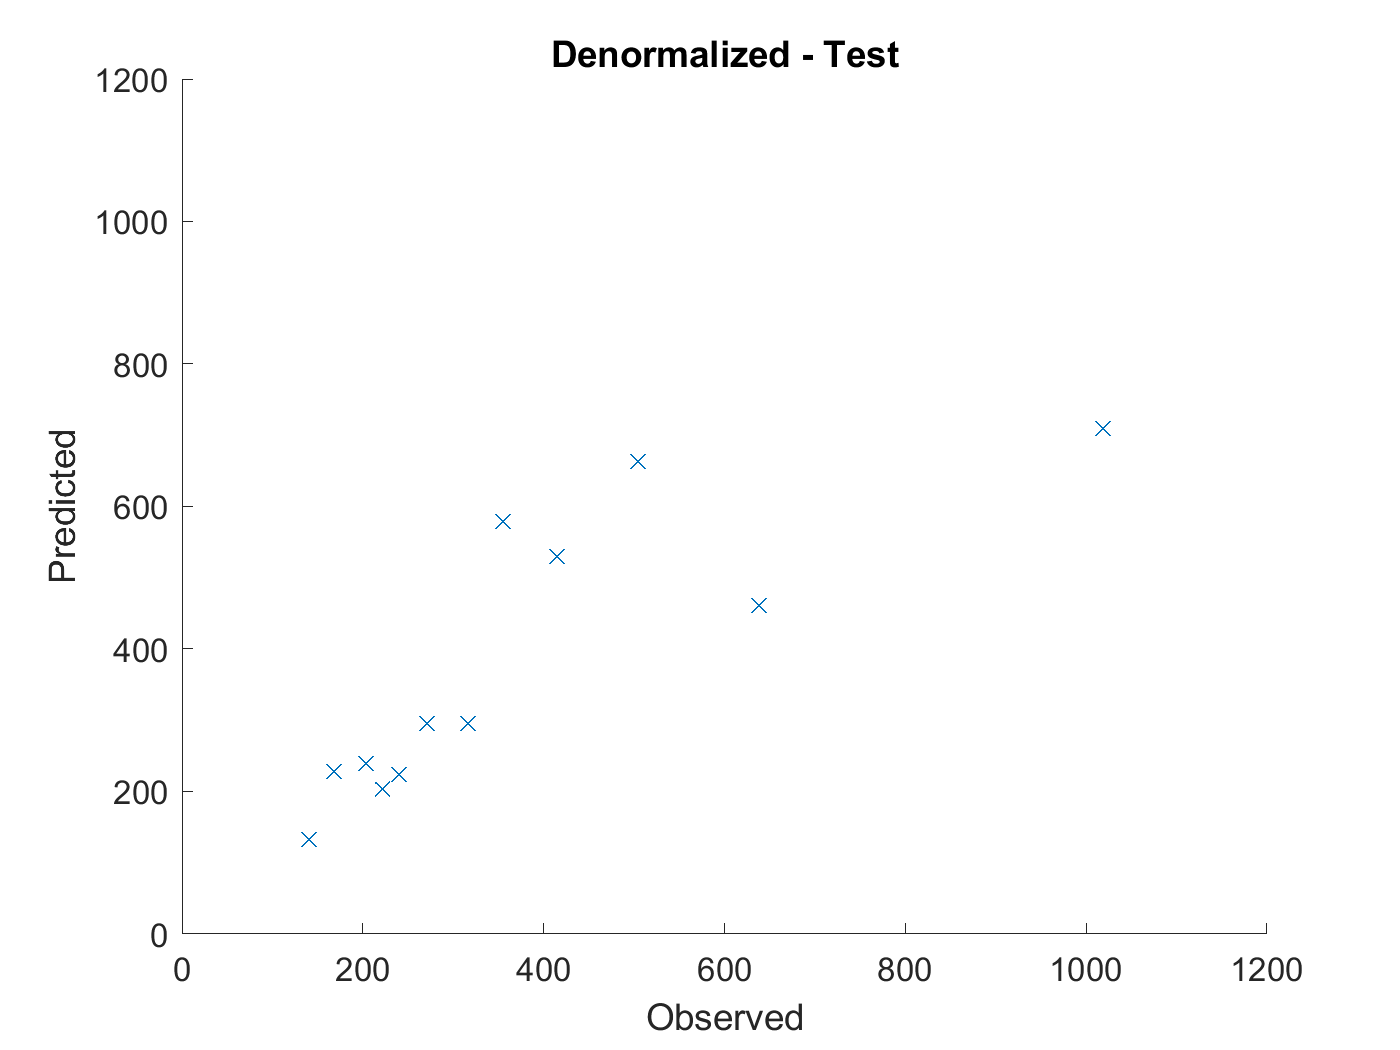


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'
xlim([0 1200]), ylim([0 1200])


% 테스트 셋에서는 예측이 전혀 안된다.

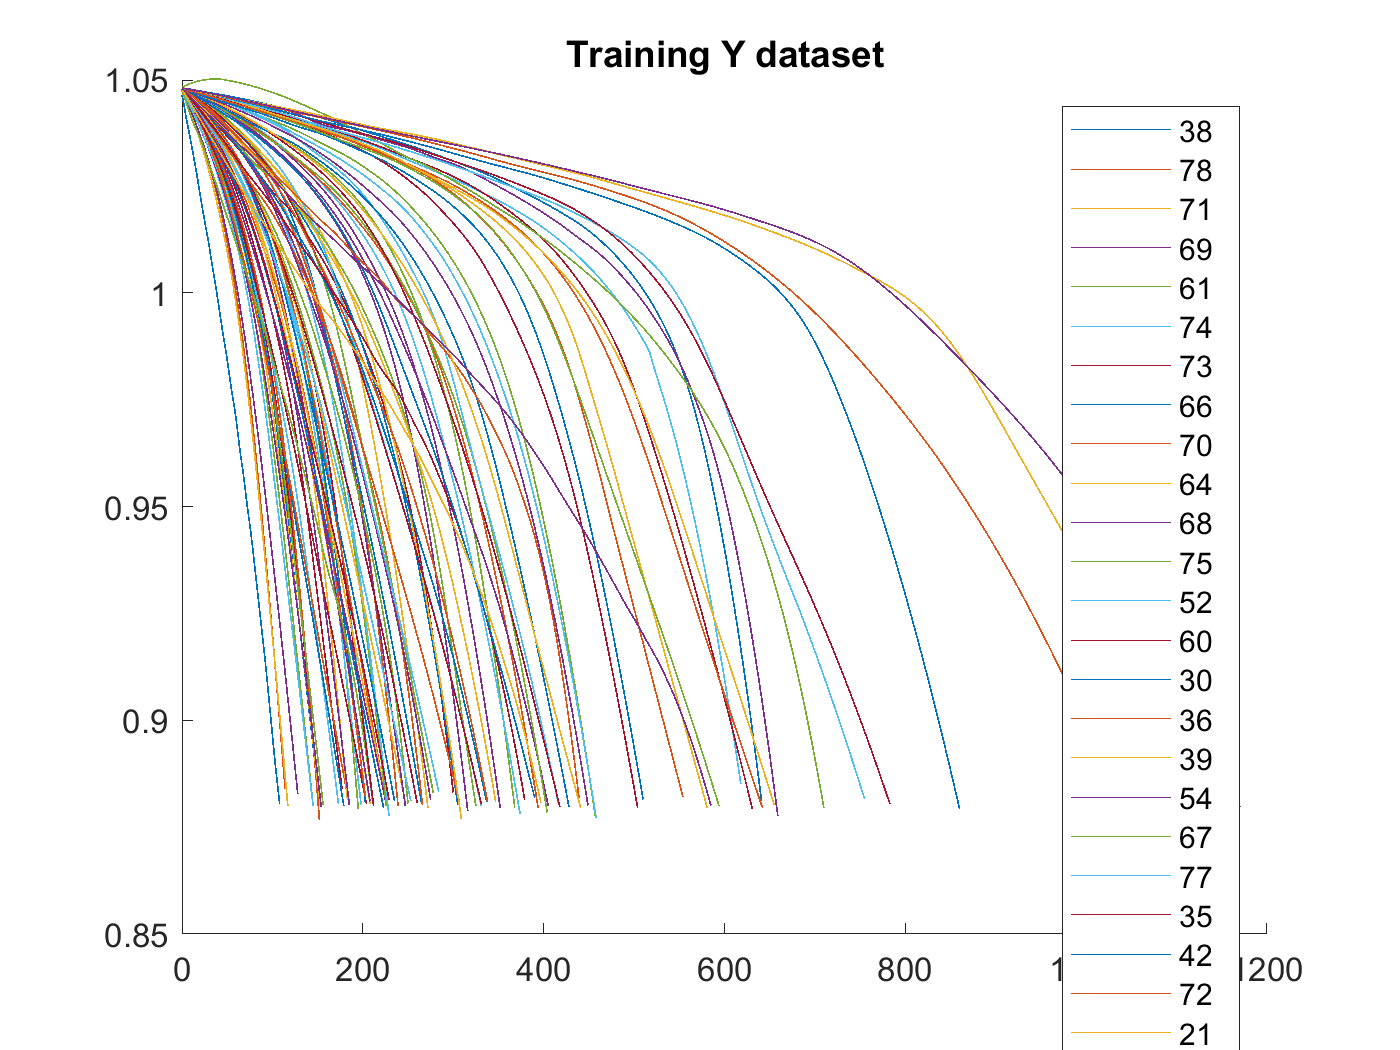

nLines = length(idxTrain);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Training Y dataset'
legend(legend_str) %,'location','NorthWest')

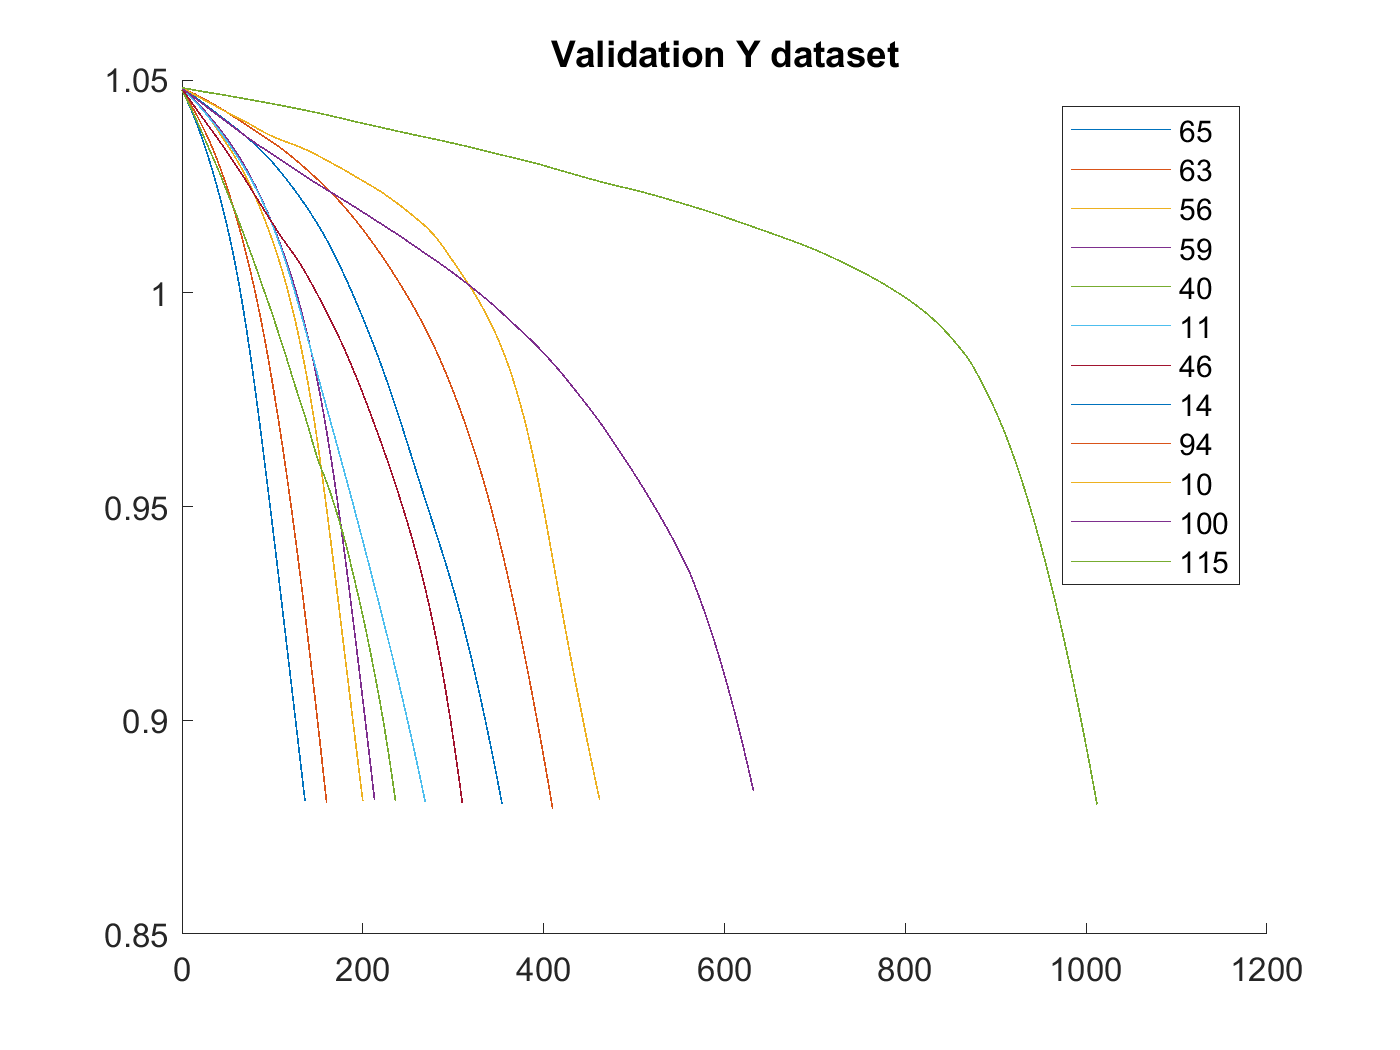

nLines = length(idxValid);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation Y dataset'


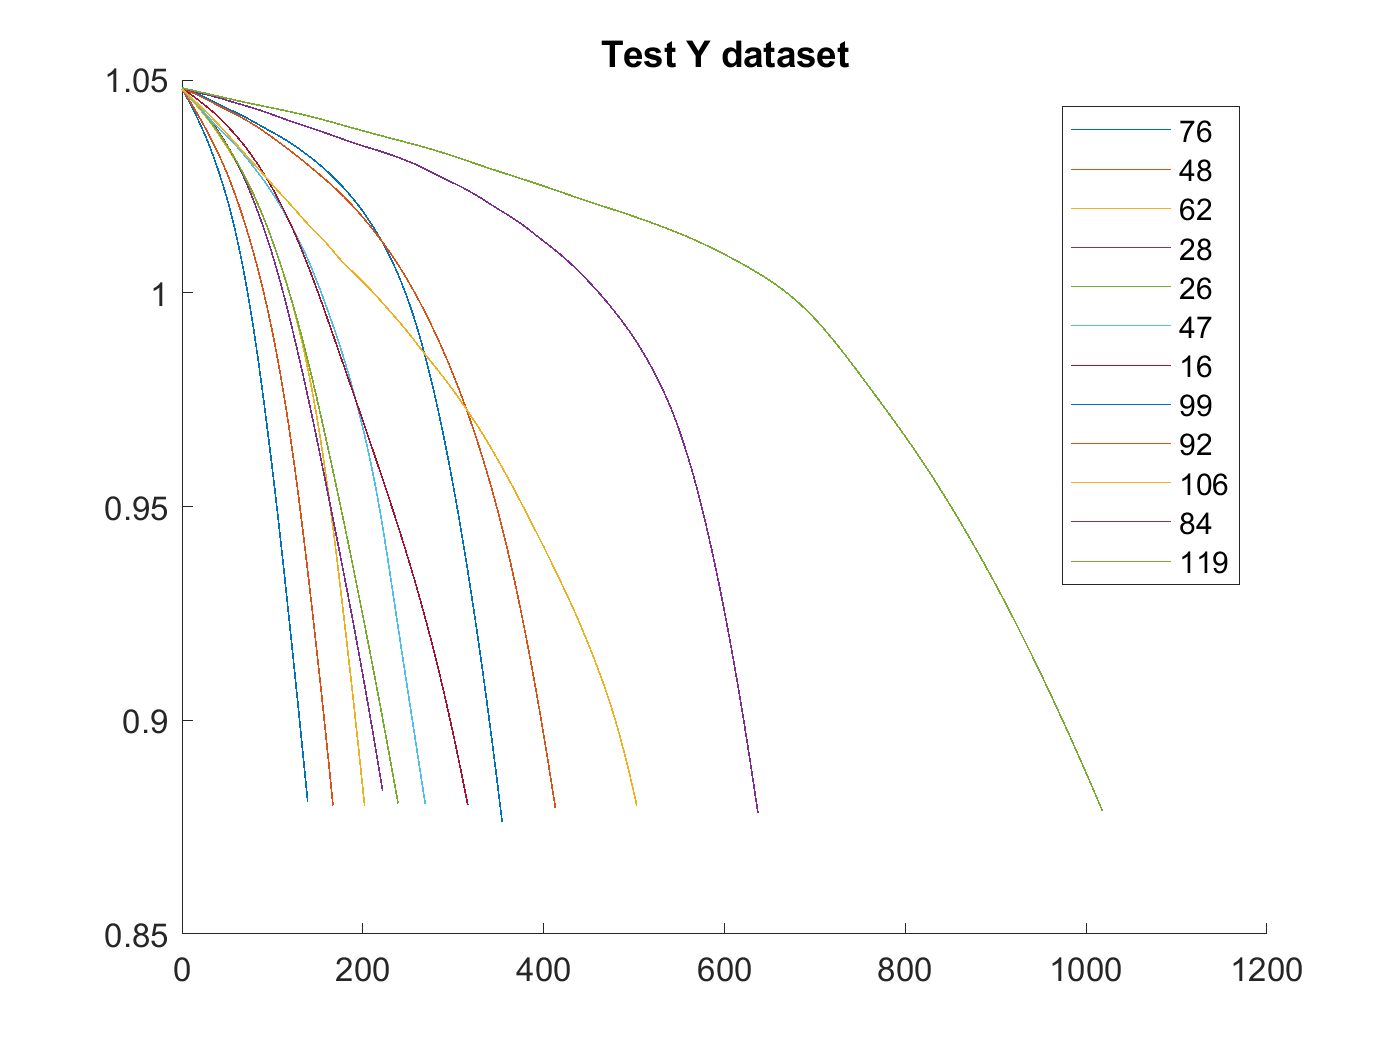


figure
nLines = length(idxTest);
legend_str = cell(nLines,1);

hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)

# 패턴 변경이 발생하지 않는 경우

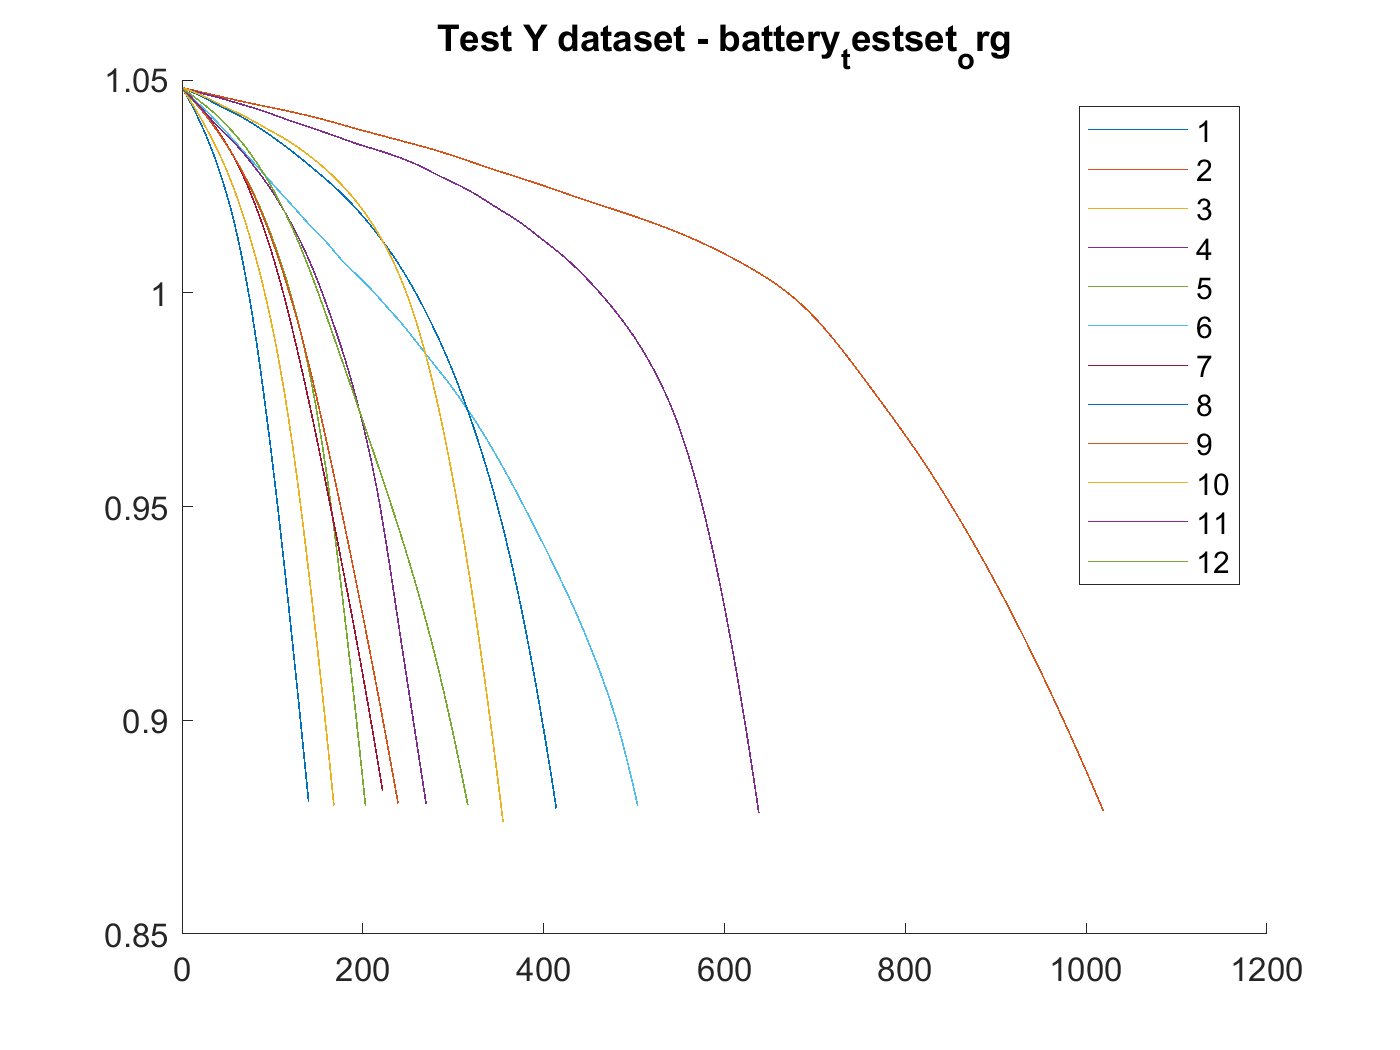

figure
nLines = length(battery_testset_org);
legend_str = cell(nLines,1);

hold on 
for j = 1 : nLines
    %i = idxTest(j);
    plot(battery_testset_org(j).QDischargeSmooth)
    legend_str{j} = num2str(j);
end
hold off
title 'Test Y dataset - battery_testset_org'
legend(legend_str)

# 패턴 변경이 발생한 경우


figure
nLines = length(battery_testset);
legend_str = cell(nLines,1);

hold on 
for j = 1 : nLines
    %i = idxTest(j);
    plot(battery_testset(j).QDischargeSmooth)
    legend_str{j} = num2str(j);
end
hold off
title 'Test Y dataset - battery_testset'
legend(legend_str)


%[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);
IcFirst_org = zeros();
IcFirst_org = battery_testset_org(1).Ic(1,:);
for i=1:length(battery_testset_org)
    IcFirst_org(i,:) = battery_testset_org(i).Ic(1,:);
end
IcFirst_org

IcFirst_org =          0    5.9990    5.9991    5.9995    6.0023    6.0014    5.9918    5.9997    5.9953    5.9987    5.9943    5.9959    6.0036    5.9999    5.9995    5.9990    5.9986    5.9981    5.9881    5.9952    5.9953    5.9947    5.9906    6.0073    5.9966    6.0091    6.0008    5.9996    5.9983    5.9898    6.0108    6.0116    5.9974    5.9952    6.0030    5.9885    6.0009    4.0000    3.9999    4.0001    3.9999    4.0000    3.9999    4.0002    4.0000    4.0005    4.0007    4.0002    4.0000    4.0001
         0    4.3646    4.3650    4.3652    4.3658    4.3649    4.3641    4.3648    4.3645    4.3643    4.3649    4.3643    4.3643    4.3653    4.3648    4.3644    4.3645    4.3644    4.3639    4.3644    4.3642    4.3642    4.3648    4.3647    4.3645    4.3648    4.3643    4.3641    4.3644    4.3648    4.3638    4.3644    4.3648    4.3648    4.3640    4.3644    4.3645    4.3649    4.3648    4.3646    4.3649    4.3643    4.3644    4.3652    4.3642    4.3649    4.3648    4.3644    4


blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


IcFirstSmall_org = blockproc(IcFirst_org, blockSize, meanFilterFunction)

IcFirstSmall_org =     4.8000    5.9974    5.9986    5.9958    5.9969    5.9995    6.0036    4.7979    4.0000    4.0003    3.9999    3.9999    4.0000    3.9658    2.4940    1.0000    0.8628    0.0791         0         0
    3.4921    4.3645    4.3647    4.3643    4.3645    4.3645    4.3644    4.3647    4.3646    4.3647    4.3649    4.3647    4.3644    4.3647    3.0191    1.0001    1.0001    0.2396         0         0
    3.3701    4.8501    4.8500    4.8500    4.8500    4.8501    4.8500    4.8499    4.8499    4.8500    4.8501    4.8500    4.7283    4.3701    2.6983    1.0000    0.9162    0.0769         0         0
    4.4809    5.6011    5.6011    5.6011    5.6010    5.6010    4.8178    4.3011    4.3001    4.3000    4.3002    4.2999    4.3002    4.3000    2.9802    1.0001    1.0000    0.1741         0         0
    4.1599    4.9923    4.7501    4.7499    4.7499    4.7500    4.7500    4.7499    4.7499    4.7500    4.7500    4.7499    4.7500    4.4587    2.7973    1.0000    0.9372    0.0


cycleLife_org = [battery_testset_org(1:end).cycle_life ]'

cycleLife_org =          140
        1019
         168
         638
         203
         504
         222
         414
         239
         355




x = IcFirstSmall_org

x =     4.8000    5.9974    5.9986    5.9958    5.9969    5.9995    6.0036    4.7979    4.0000    4.0003    3.9999    3.9999    4.0000    3.9658    2.4940    1.0000    0.8628    0.0791         0         0
    3.4921    4.3645    4.3647    4.3643    4.3645    4.3645    4.3644    4.3647    4.3646    4.3647    4.3649    4.3647    4.3644    4.3647    3.0191    1.0001    1.0001    0.2396         0         0
    3.3701    4.8501    4.8500    4.8500    4.8500    4.8501    4.8500    4.8499    4.8499    4.8500    4.8501    4.8500    4.7283    4.3701    2.6983    1.0000    0.9162    0.0769         0         0
    4.4809    5.6011    5.6011    5.6011    5.6010    5.6010    4.8178    4.3011    4.3001    4.3000    4.3002    4.2999    4.3002    4.3000    2.9802    1.0001    1.0000    0.1741         0         0
    4.1599    4.9923    4.7501    4.7499    4.7499    4.7500    4.7500    4.7499    4.7499    4.7500    4.7500    4.7499    4.7500    4.4587    2.7973    1.0000    0.9372    0.0781         0  

y = cycleLife_org

y =          140
        1019
         168
         638
         203
         504
         222
         414
         239
         355


[ynorm_org,xnorm_org] = minmax_norm_new_with_param(y,x,ymin,yrate,xmin,xrate);


IcFirst_change = zeros();
IcFirst_change = battery_testset(1).Ic(1,:);
for i=1:length(battery_testset)
    IcFirst_change(i,:) = battery_testset(i).Ic(1,:);
end
IcFirst_change

IcFirst_change =          0    5.9990    5.9991    5.9995    6.0023    6.0014    5.9918    5.9997    5.9953    5.9987    5.9943    5.9959    6.0036    5.9999    5.9995    5.9990    5.9986    5.9981    5.9881    5.9952    5.9953    5.9947    5.9906    6.0073    5.9966    6.0091    6.0008    5.9996    5.9983    5.9898    6.0108    6.0116    5.9974    5.9952    6.0030    5.9885    6.0009    4.0000    3.9999    4.0001    3.9999    4.0000    3.9999    4.0002    4.0000    4.0005    4.0007    4.0002    4.0000    4.0001
         0    4.3646    4.3650    4.3652    4.3658    4.3649    4.3641    4.3648    4.3645    4.3643    4.3649    4.3643    4.3643    4.3653    4.3648    4.3644    4.3645    4.3644    4.3639    4.3644    4.3642    4.3642    4.3648    4.3647    4.3645    4.3648    4.3643    4.3641    4.3644    4.3648    4.3638    4.3644    4.3648    4.3648    4.3640    4.3644    4.3645    4.3649    4.3648    4.3646    4.3649    4.3643    4.3644    4.3652    4.3642    4.3649    4.3648    4.3644  


blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


IcFirstSmall_change = blockproc(IcFirst_change, blockSize, meanFilterFunction)

IcFirstSmall_change =     4.8000    5.9974    5.9986    5.9958    5.9969    5.9995    6.0036    4.7979    4.0000    4.0003    3.9999    3.9999    4.0000    3.9658    2.4940    1.0000    0.8628    0.0791         0         0
    3.4921    4.3645    4.3647    4.3643    4.3645    4.3645    4.3644    4.3647    4.3646    4.3647    4.3649    4.3647    4.3644    4.3647    3.0191    1.0001    1.0001    0.2396         0         0
    3.3701    4.8501    4.8500    4.8500    4.8500    4.8501    4.8500    4.8499    4.8499    4.8500    4.8501    4.8500    4.7283    4.3701    2.6983    1.0000    0.9162    0.0769         0         0
    4.4809    5.6011    5.6011    5.6011    5.6010    5.6010    4.8178    4.3011    4.3001    4.3000    4.3002    4.2999    4.3002    4.3000    2.9802    1.0001    1.0000    0.1741         0         0
    4.1599    4.9923    4.7501    4.7499    4.7499    4.7500    4.7500    4.7499    4.7499    4.7500    4.7500    4.7499    4.7500    4.4587    2.7973    1.0000    0.9372    


cycleLife_change = [battery_testset(1:end).cycle_life ]'

cycleLife_change =    423
   738
   267
   541
   411
   298
   267
   371
   225
   371




x = IcFirstSmall_change

x =     4.8000    5.9974    5.9986    5.9958    5.9969    5.9995    6.0036    4.7979    4.0000    4.0003    3.9999    3.9999    4.0000    3.9658    2.4940    1.0000    0.8628    0.0791         0         0
    3.4921    4.3645    4.3647    4.3643    4.3645    4.3645    4.3644    4.3647    4.3646    4.3647    4.3649    4.3647    4.3644    4.3647    3.0191    1.0001    1.0001    0.2396         0         0
    3.3701    4.8501    4.8500    4.8500    4.8500    4.8501    4.8500    4.8499    4.8499    4.8500    4.8501    4.8500    4.7283    4.3701    2.6983    1.0000    0.9162    0.0769         0         0
    4.4809    5.6011    5.6011    5.6011    5.6010    5.6010    4.8178    4.3011    4.3001    4.3000    4.3002    4.2999    4.3002    4.3000    2.9802    1.0001    1.0000    0.1741         0         0
    4.1599    4.9923    4.7501    4.7499    4.7499    4.7500    4.7500    4.7499    4.7499    4.7500    4.7500    4.7499    4.7500    4.4587    2.7973    1.0000    0.9372    0.0781         0  

y = cycleLife_change

y =    423
   738
   267
   541
   411
   298
   267
   371
   225
   371


[ynorm_change,xnorm_change] = minmax_norm_new_with_param(y,x,ymin,yrate,xmin,xrate);


yfit_org = predict(mdl,xnorm_org);

yfit_org =     0.0222
    0.5660
    0.1122
    0.3312
    0.1233
    0.5218
    0.0877
    0.3961
    0.1083
    0.4429


yfit_change = predict(mdl,xnorm_change);

yfit_change =     0.0222
    0.5660
    0.1122
    0.3312
    0.1233
    0.5218
    0.0877
    0.3961
    0.1083
    0.4429



y_org = ynorm_org* yrate + ymin;
y_change = ynorm_change* yrate + ymin;
yfit_org = yfit_org * yrate + ymin;
yfit_change = yfit_change * yrate + ymin;

yfit_rmse_org = sqrt(mean((y_org - yfit_org).^2)) 

yfit_rmse_org = 136.1904

yfit_change_rmse = sqrt(mean((y_change - yfit_change).^2)) 

yfit_change_rmse = 165.8126


y_org_diff = horzcat(y_org, (y_org - yfit_org))

y_org_diff = 	1.0e+03 *

    0.1400    0.0075
    1.0190    0.3089
    0.1680   -0.0601
    0.6380    0.1772
    0.2030   -0.0370
    0.5040   -0.1591
    0.2220    0.0198
    0.4140   -0.1157
    0.2390    0.0150
    0.3550   -0.2244


y_org_diff_percentage = abs(y_org - yfit_org)./y_org

y_org_diff_percentage =     0.0533
    0.3031
    0.3580
    0.2778
    0.1820
    0.3157
    0.0893
    0.2794
    0.0628
    0.6320


y_org_diff_percentage_avg = sum(y_org_diff_percentage)/length(y_org_diff_percentage)

y_org_diff_percentage_avg = 0.2260


y_change_diff = horzcat(y_change, (y_change - yfit_change))

y_change_diff =   423.0000  290.4567
  738.0000   27.8660
  267.0000   38.8551
  541.0000   80.2339
  411.0000  171.0483
  298.0000 -365.1358
  267.0000   64.8146
  371.0000 -158.6770
  225.0000    0.9991
  371.0000 -208.3624


y_change_diff_percentage = abs(y_change - yfit_change)./y_change

y_change_diff_percentage =     0.6867
    0.0378
    0.1455
    0.1483
    0.4162
    1.2253
    0.2428
    0.4277
    0.0044
    0.5616


y_change_diff_percentage_avg = sum(y_change_diff_percentage)/length(y_change_diff_percentage)

y_change_diff_percentage_avg = 0.3402

# 사용자패턴이 변경된 경우 좀 더 잘못 예측한다.RMSE 값이 올라간다. 다른 논문과 비교해서 성능평가를 해야 한다. 2 point로 RUL 예측한 논문과. 하지만 사용자패턴의 변경과 관계없이 첫번째 충전패턴으로 RUL을 예측한 것은 의미가 있다.


% here

idxTrainRand_new = idxTrainRand(1:80);
idxValidRand_new = idxTrainRand(81:end);
idxTestRand_new = [ idxValidRand idxTestRand]

idxTestRand_new =     94    63   100    46   115    65    10    14    11    40    56    59    26   106    28    76   119    84    47    62    92    16    48    99


- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand_new;
netFNN1_1.divideParam.valInd = idxValidRand_new;
netFNN1_1.divideParam.testInd = idxTestRand_new; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = tr.trainInd;
netFNN1_2.divideParam.valInd = tr.valInd;
netFNN1_2.divideParam.testInd = tr.testInd; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = tr.trainInd;
netFNN1_3.divideParam.valInd = tr.valInd;
netFNN1_3.divideParam.testInd = tr.testInd; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_3, tr3] = train(netFNN1_3, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
[netFNN2_1, tr2] = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
netFNN2_2 = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
netFNN3_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
netFNN4_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
netFNN5_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

pFNN1_1 = netFNN1_1(xnorm(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm(tr.testInd, :)');
pFNN2_1 = netFNN2_1(xnorm(tr.testInd, :)');
pFNN2_2 = netFNN2_2(xnorm(tr.testInd, :)');
pFNN3_1 = netFNN3_1(xnorm(tr.testInd, :)');
pFNN4_1 = netFNN4_1(xnorm(tr.testInd, :)');
pFNN5_1 = netFNN5_1(xnorm(tr.testInd, :)');

ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
pFNN1_2_hat = pFNN1_2 * yrate + ymin;
pFNN1_3_hat = pFNN1_3 * yrate + ymin;
pFNN2_1_hat = pFNN2_1 * yrate + ymin;
pFNN2_2_hat = pFNN2_2 * yrate + ymin;
pFNN3_1_hat = pFNN3_1 * yrate + ymin;
pFNN4_1_hat = pFNN4_1 * yrate + ymin;
pFNN5_1_hat = pFNN5_1 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 157.0085

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 280.0875

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 213.4366

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 173.4917

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 173.4917

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 174.5473

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 174.5473

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 174.5473

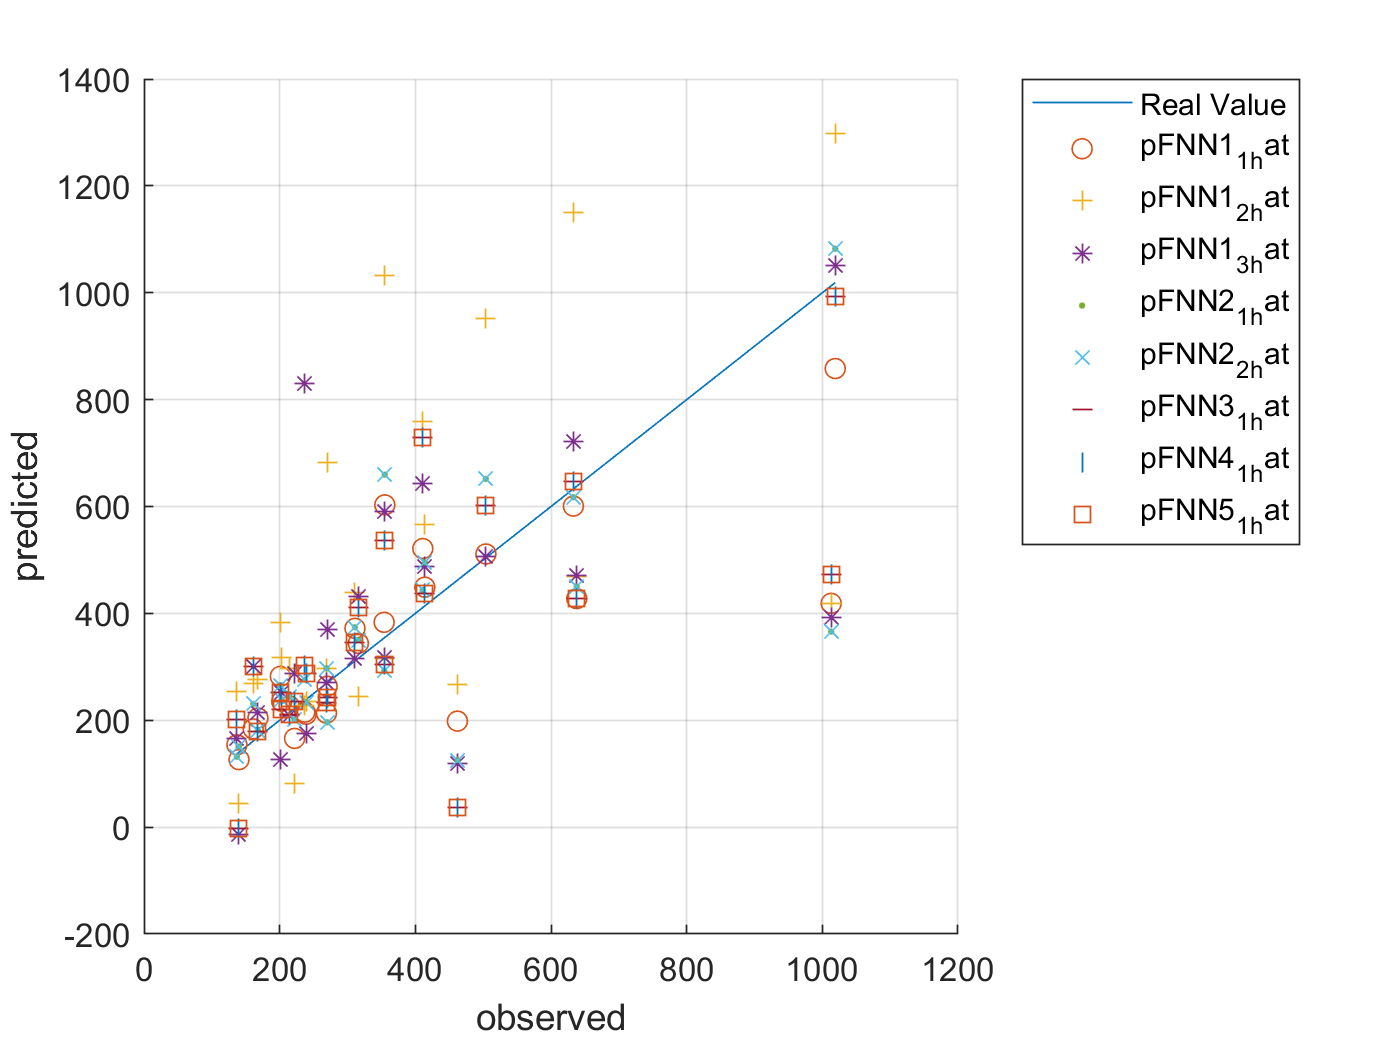


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN1_1' )
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN1_2' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN1_3' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN2_1' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN2_2' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN3_1' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN4_1' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netFNN5_1' ,'-append')

pFNN1_1_self = netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_1_self = netFNN2_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_2_self = netFNN2_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN3_1_self = netFNN3_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN4_1_self = netFNN4_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN5_1_self = netFNN5_1(xnorm([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
pFNN1_2_self_hat = pFNN1_2_self * yrate + ymin;
pFNN1_3_self_hat = pFNN1_3_self * yrate + ymin;
pFNN2_1_self_hat = pFNN2_1_self * yrate + ymin;
pFNN2_2_self_hat = pFNN2_2_self * yrate + ymin;
pFNN3_1_self_hat = pFNN3_1_self * yrate + ymin;
pFNN4_1_self_hat = pFNN4_1_self * yrate + ymin;
pFNN5_1_self_hat = pFNN5_1_self * yrate + ymin;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 107.5807

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 196.8302

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 124.9595

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 98.3556

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 98.3556

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 98.9396

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 98.9396

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 98.9396

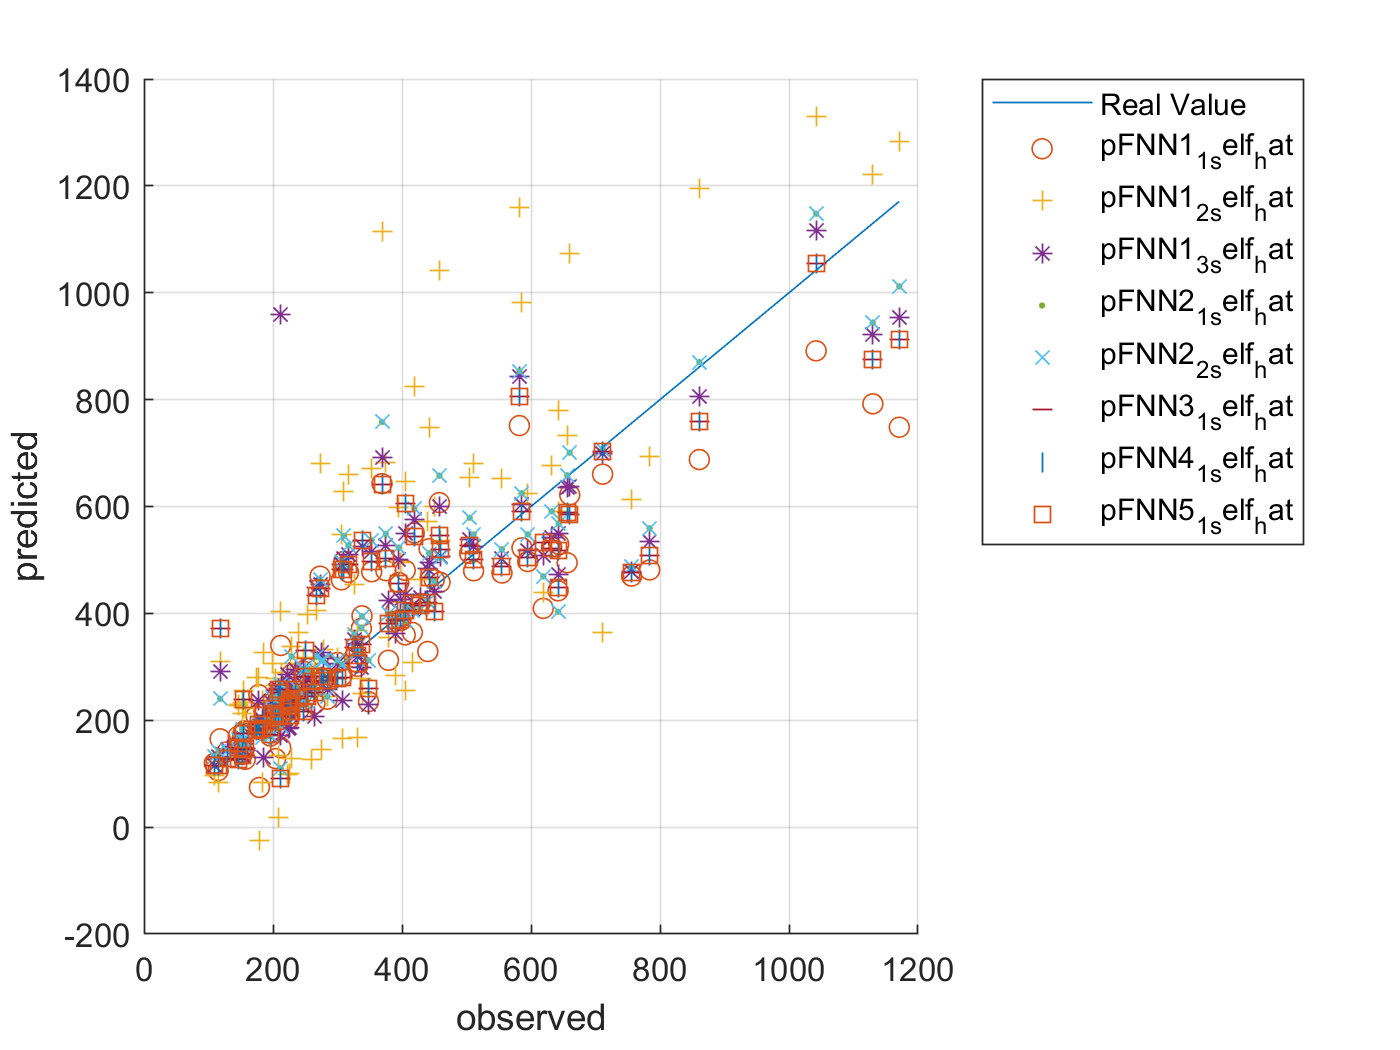



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

filterSize = 3;
numFilters = 32;
numFCN = 1;
cc_input_size = 20;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.39 |         0.25 |       0.0755 |       0.0320 |          0.0010 |
|      50 |          50 |       00:00:18 |         0.21 |         0.19 |       0.0213 |       0.0174 |          0.0010 |
|     100 |         100 |       00:00:20 |         0.20 |         0.17 |       0.0196 |       0.0151 |          0.0010 |
|     150 |         150 |       00:00:25 |         0.19 |         0.17 |       0.0181 |   

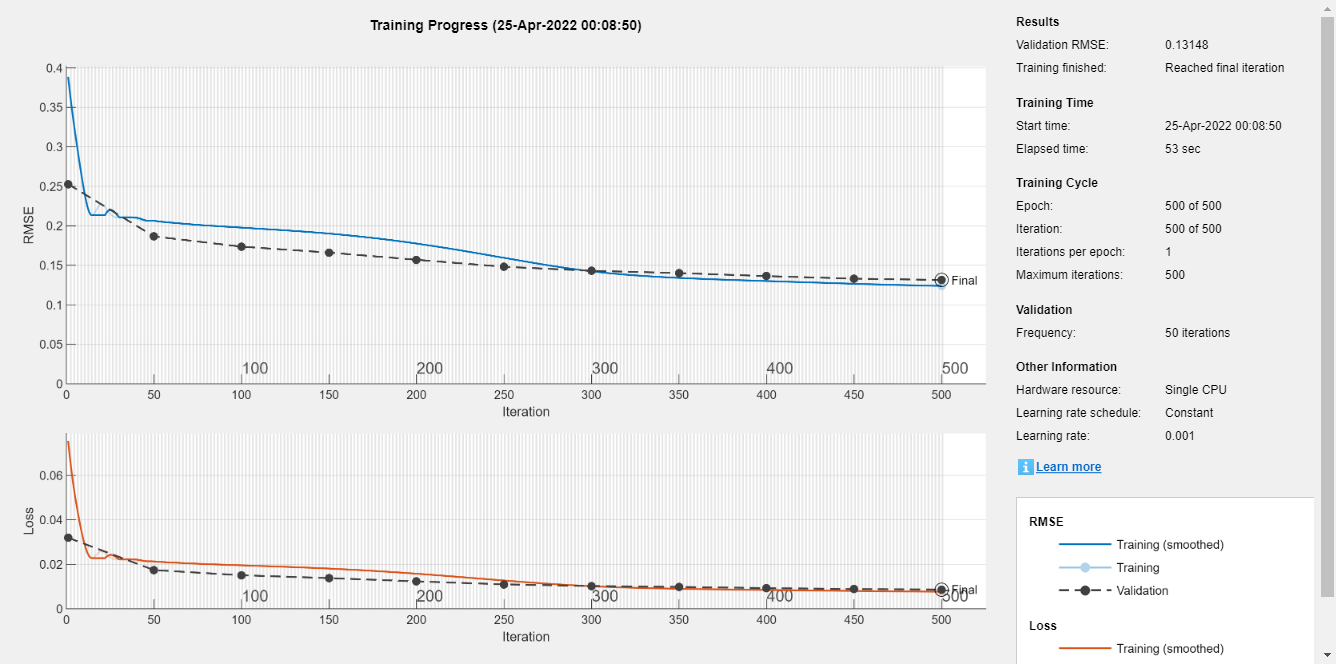



layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |         0.26 |         0.18 |       0.0330 |       0.0162 |          0.0010 |
|      50 |          50 |       00:00:19 |         0.18 |         0.15 |       0.0158 |       0.0110 |          0.0010 |
|     100 |         100 |       00:00:21 |         0.16 |         0.14 |       0.0127 |       0.0098 |          0.0010 |
|     150 |         150 |       00:00:27 |         0.14 |         0.13 |       0.0095 |   

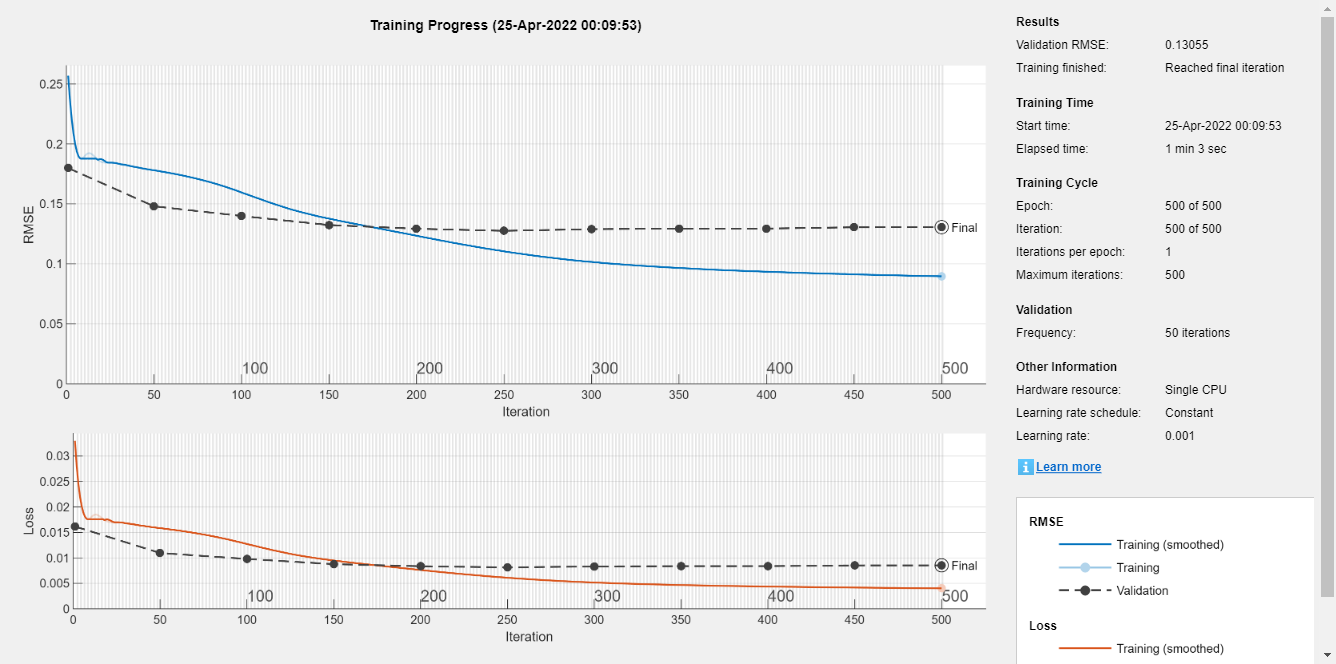

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.29 |         0.18 |       0.0409 |       0.0164 |          0.0010 |
|      50 |          50 |       00:00:18 |         0.20 |         0.17 |       0.0205 |       0.0147 |          0.0010 |
|     100 |         100 |       00:00:25 |         0.19 |         0.17 |       0.0188 |       0.0139 |          0.0010 |
|     150 |         150 |       00:00:31 |         0.18 |         0.16 |       0.0171 |   

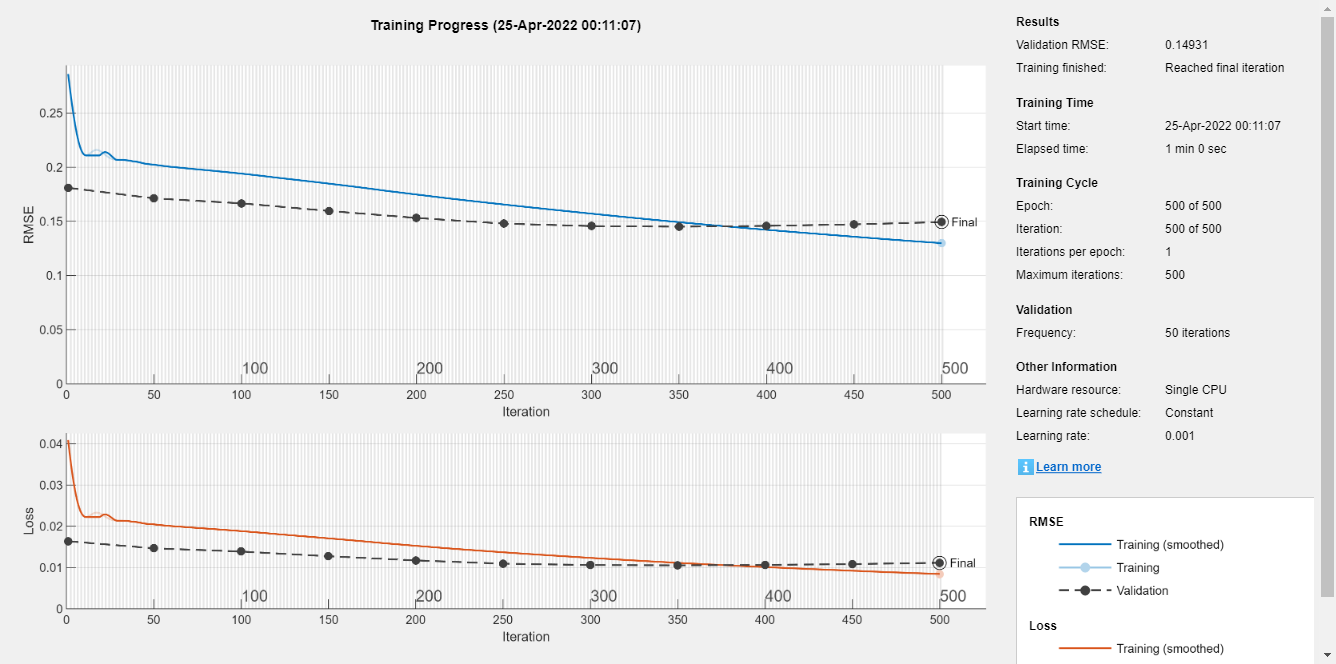





layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);



layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         1.14 |         0.61 |       0.6475 |       0.1864 |          0.0010 |
|      50 |          50 |       00:00:19 |         0.19 |         0.16 |       0.0181 |       0.0127 |          0.0010 |
|     100 |         100 |       00:00:25 |         0.18 |         0.16 |       0.0157 |       0.0123 |          0.0010 |
|     150 |         150 |       00:00:34 |         0.17 |         0.16 |       0.0149 |   

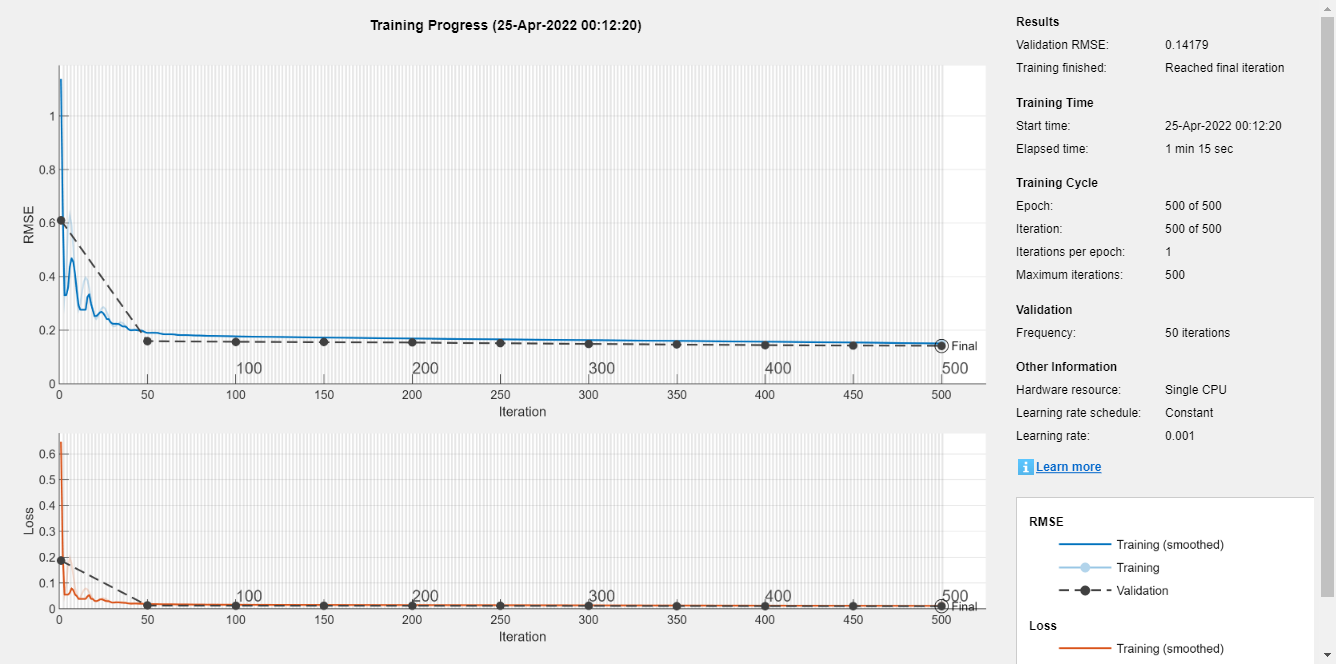

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:17 |         0.82 |         1.52 |       0.3324 |       1.1583 |          0.0010 |
|      50 |          50 |       00:00:26 |         0.21 |         0.21 |       0.0226 |       0.0213 |          0.0010 |
|     100 |         100 |       00:00:34 |         0.19 |         0.16 |       0.0190 |       0.0127 |          0.0010 |
|     150 |         150 |       00:00:41 |         0.19 |         0.15 |       0.0175 |       0.0118 |          0.0010 |
|     200 |         200 |       00:00:49 |         0.18 |         0.15 |       0.0161 |       0.0109 |          0.0010 |
|     250 |         250 |       00:00:55 |         0.17 |         0.14 |       0.0148 |       0.0099 |          0.0010 |
|     300 |         300 |       00:01:02 |         0.17 |         0.14 |       0.0137 |       0.0094 |          0.0010 |
|     350 |         350 |       00:01:06 |         0.16 |         0.13 |       0.0126 |       0.0091 |          0.0010 |
|     400 |         400 |       

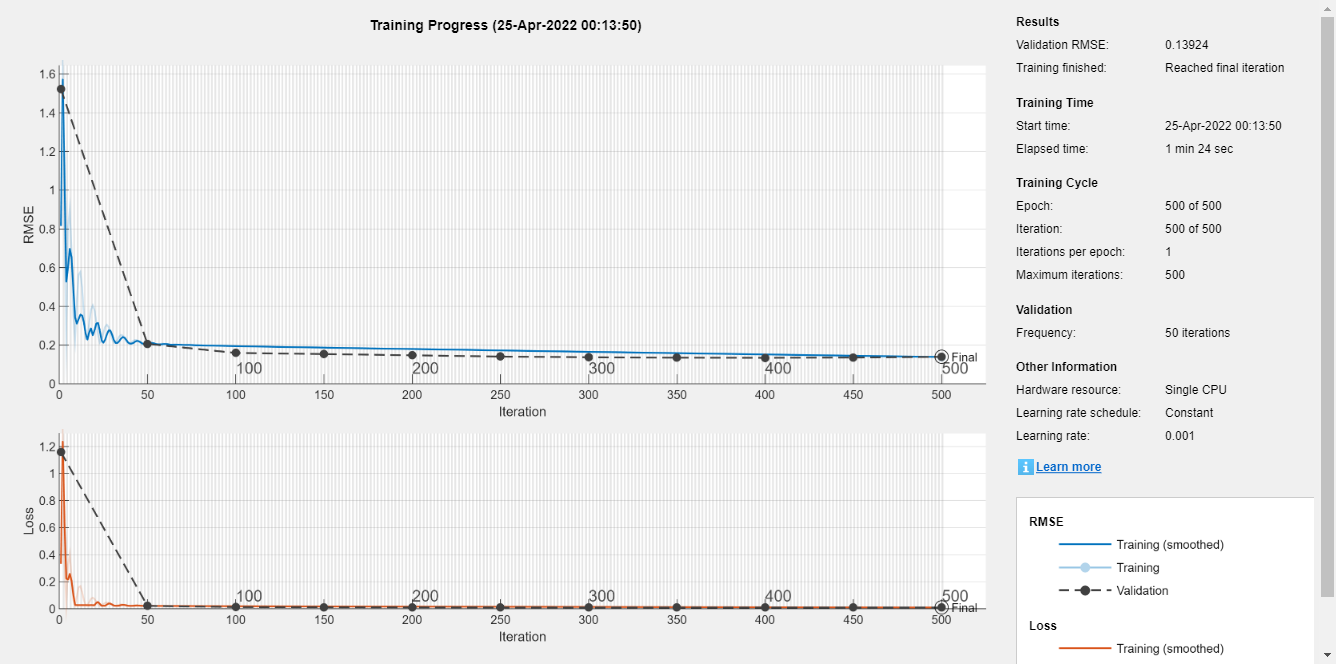


layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

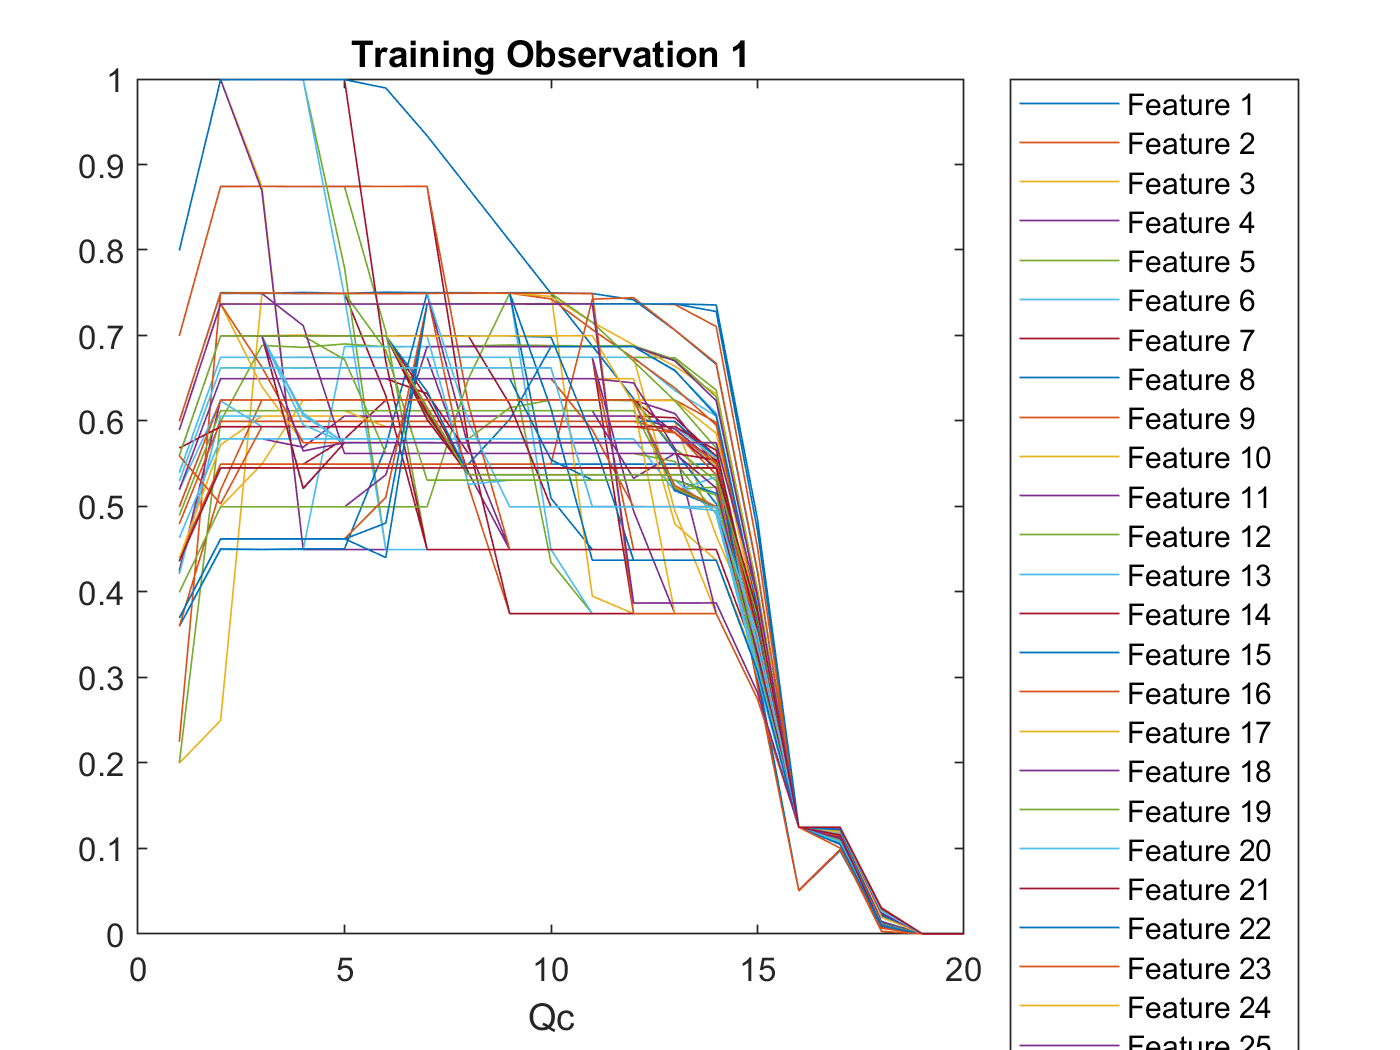


figure
plot(xnorm')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")



cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
pCNN2_3 = predict(netCNN2_3, x_4d);
pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);


pCNN2_2_1  = predict(netCNN2_1  , x_4d)

pCNN2_2_1 = 24×1 single column vector
    0.4655
    0.4521
    0.2227
    0.2737
    0.1226
    0.1908
    0.0860
    0.2376
    0.3134
    0.1133


pCNN2_2_2  = predict(netCNN2_2  , x_4d)

pCNN2_2_2 = 24×1 single column vector
    0.0567
    0.1164
    0.1995
    0.2609
    0.1058
    0.1251
    0.2359
    0.2388
    0.2237
    0.0279


pCNN2_2_3  = predict(netCNN2_3  , x_4d)

pCNN2_2_3 = 24×1 single column vector
    0.2041
    0.2242
    0.1019
    0.1799
    0.0879
    0.1509
    0.1576
    0.3342
    0.2197
    0.1686


pCNN2_2_4  = predict(netCNN2_4  , x_4d)

pCNN2_2_4 = 24×1 single column vector
    0.0047
    0.1410
    0.1375
    0.2116
    0.0376
    0.1224
    0.1450
    0.2982
    0.2549
    0.0709


pCNN2_1_1  = predict(netCNN1_1  , x_4d)

pCNN2_1_1 = 24×1 single column vector
   -0.0409
    0.1895
    0.2718
    0.2303
    0.2004
    0.1560
    0.2321
    0.3185
    0.3970
    0.0876



ytest = ynorm(tr.testInd, :)*yrate + ymin;
pCNN2_2_1_hat = pCNN2_2_1 * yrate + ymin;
pCNN2_2_2_hat = pCNN2_2_2 * yrate + ymin;
pCNN2_2_3_hat = pCNN2_2_3 * yrate + ymin;
pCNN2_2_4_hat = pCNN2_2_4 * yrate + ymin;
pCNN2_1_1_hat = pCNN2_1_1 * yrate + ymin;


rmse_pCNN2_2_1_hat = sqrt(mean(( ytest' - pCNN2_2_1_hat' ).^2))

rmse_pCNN2_2_1_hat = single
196.6237

rmse_pCNN2_2_2_hat = sqrt(mean(( ytest' - pCNN2_2_2_hat' ).^2))

rmse_pCNN2_2_2_hat = single
161.0177

rmse_pCNN2_2_3_hat = sqrt(mean(( ytest' - pCNN2_2_3_hat' ).^2))

rmse_pCNN2_2_3_hat = single
212.7308

rmse_pCNN2_2_4_hat = sqrt(mean(( ytest' - pCNN2_2_4_hat' ).^2))

rmse_pCNN2_2_4_hat = single
165.1784

rmse_pCNN2_1_1_hat = sqrt(mean(( ytest' - pCNN2_1_1_hat' ).^2))

rmse_pCNN2_1_1_hat = single
189.9642

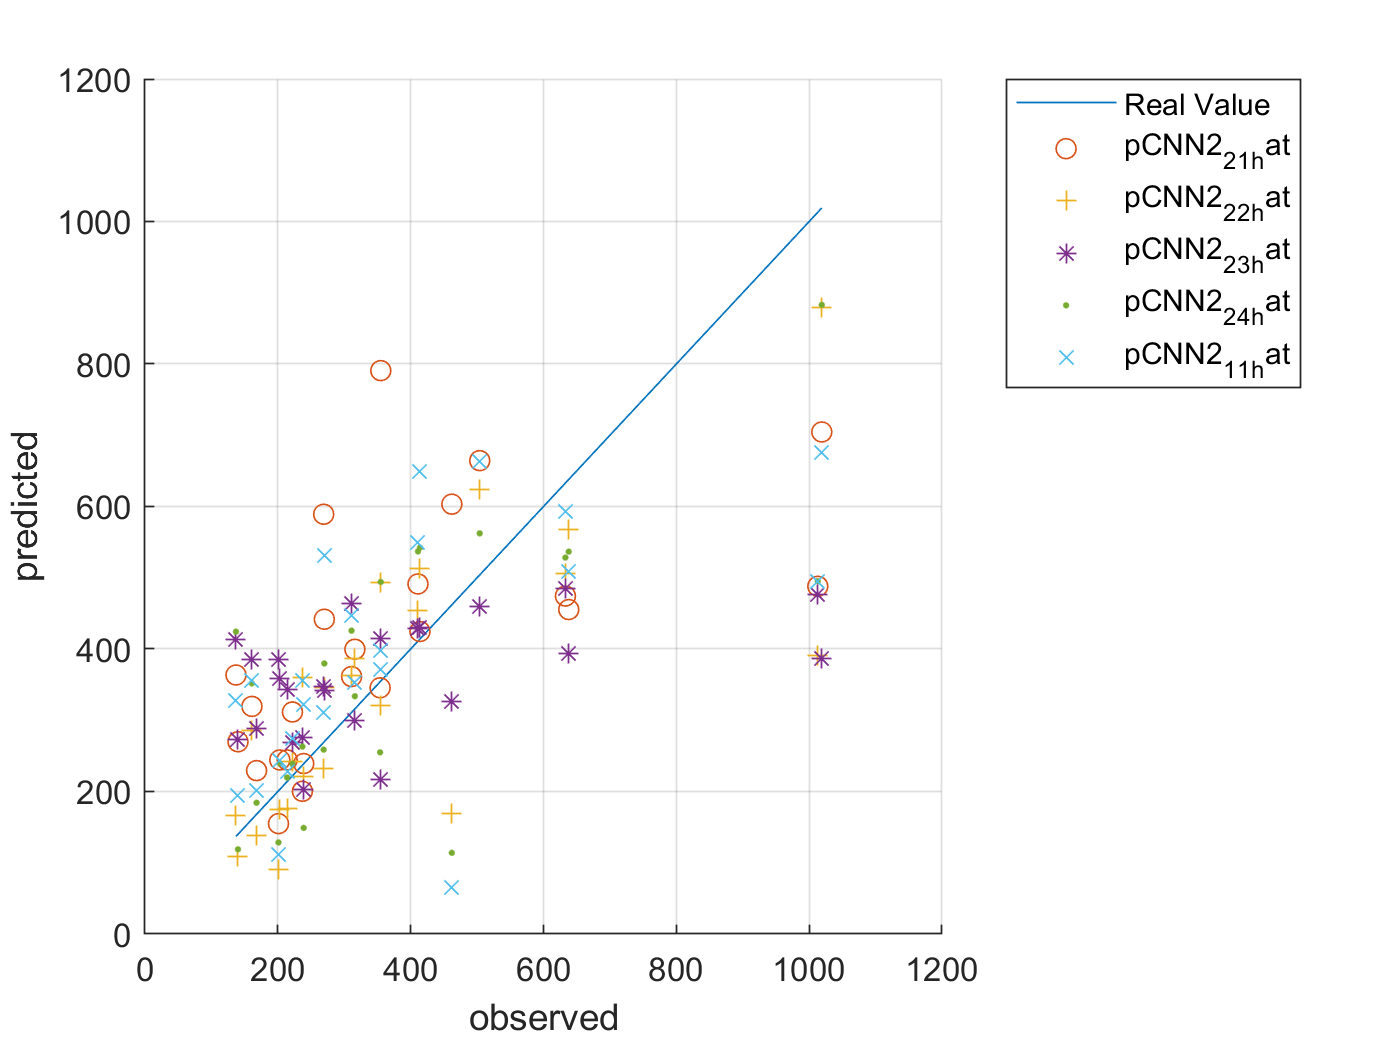




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_2_1_hat,'o')
plot(ytest,pCNN2_2_2_hat,'+')
plot(ytest,pCNN2_2_3_hat,'*')
plot(ytest,pCNN2_2_4_hat,'.')
plot(ytest,pCNN2_1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_2_1_hat', ... 
		'pCNN2_2_2_hat', ...
		'pCNN2_2_3_hat', ... 	
		'pCNN2_2_4_hat', ... 
		'pCNN2_1_1_hat','Location','northeastoutside')




save('ryan3_model_1stCC_cyclelife_v1.mat','netCNN2_1' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netCNN2_2' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netCNN2_3' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netCNN2_4' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netCNN1_1' ,'-append')

cellx_self = num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pCNN2_1_self_hat = pCNN2_1_self * yrate + ymin;
pCNN2_2_self_hat = pCNN2_2_self * yrate + ymin;
pCNN2_3_self_hat = pCNN2_3_self * yrate + ymin;
pCNN2_4_self_hat = pCNN2_4_self * yrate + ymin;
pCNN1_1_self_hat = pCNN1_1_self * yrate + ymin;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
186.1726

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
140.9828

rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))

rmse_pCNN2_3_self_hat = single
190.7766

rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))

rmse_pCNN2_4_self_hat = single
153.8058

rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
182.0337

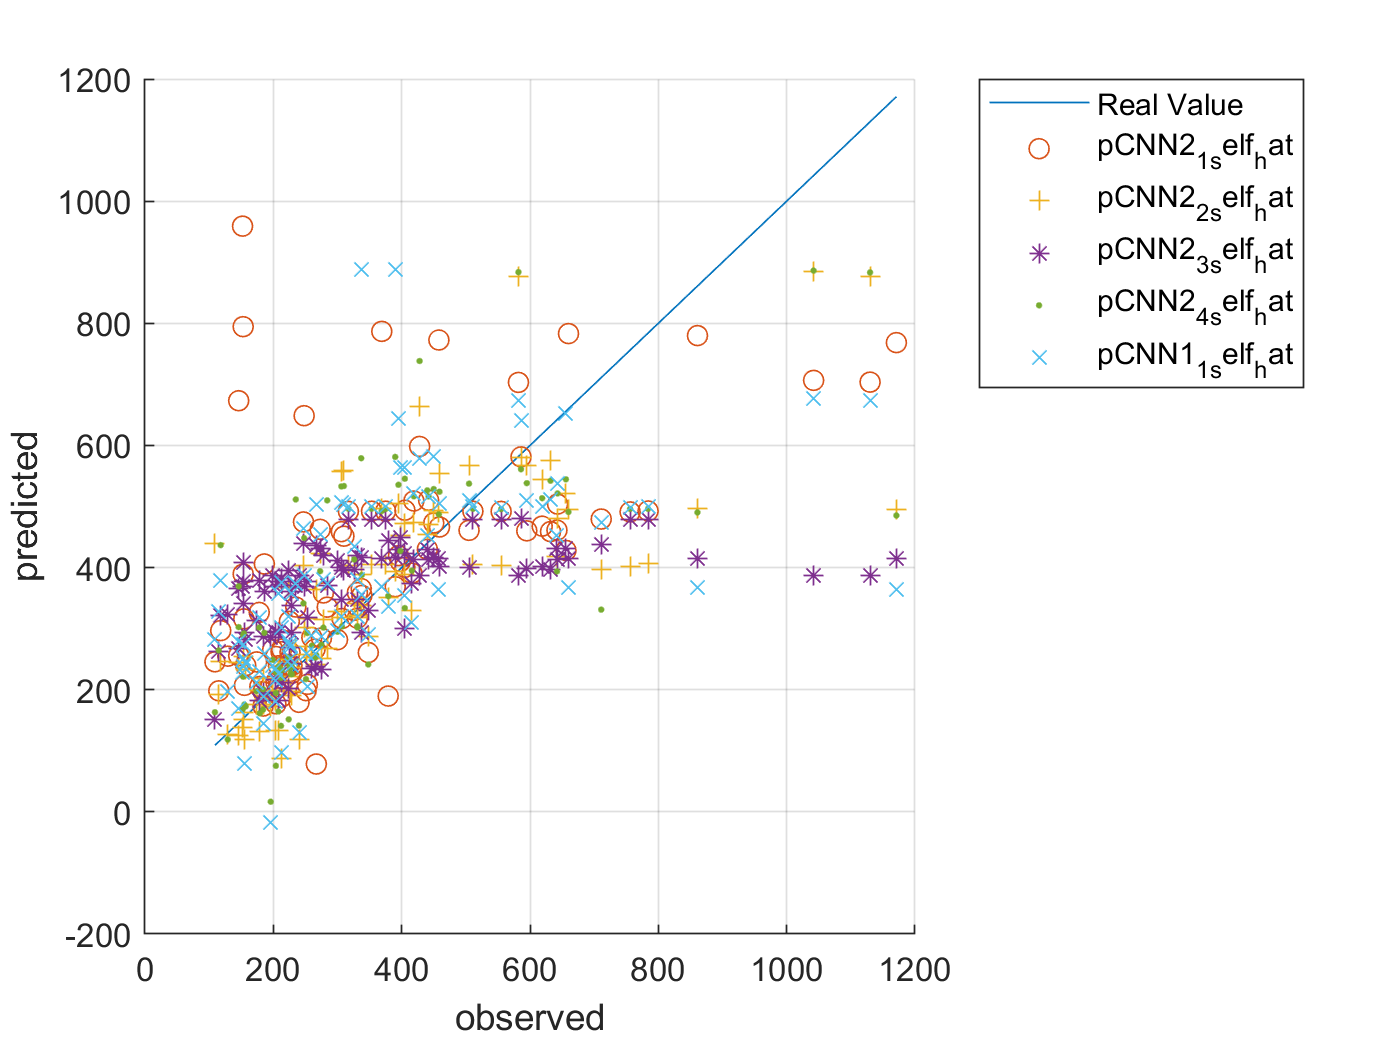




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	
		'pCNN2_4_self_hat', ... 
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:19 |         0.37 |         0.22 |       0.0696 |       0.0236 |          0.0010 |
|      50 |          50 |       00:00:29 |         0.23 |         0.18 |       0.0262 |       0.0163 |          0.0010 |
|     100 |         100 |       00:00:37 |         0.23 |         0.18 |       0.0255 |       0.0170 |          0.0010 |
|     150 |         150 |       00:00:41 |         0.22 |         0.19 |       0.0249 |       0.0175 |          0.0010 |
|     20

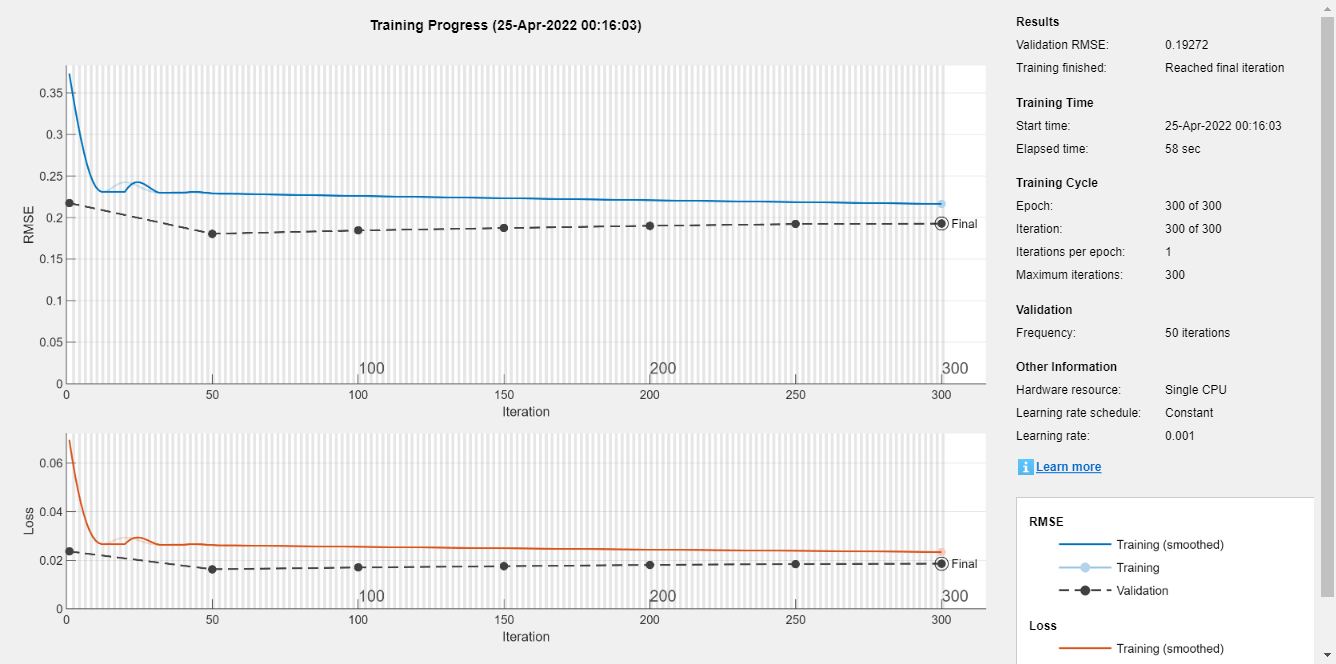

cc_input_size = 20;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',300, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.28 |         0.22 |       0.0388 |       0.0246 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.19 |         0.15 |       0.0172 |       0.0106 |          0.0010 |
|     100 |         100 |       00:00:27 |         0.18 |         0.15 |       0.0170 |       0.0107 |          0.0010 |
|     150 |         150 |       00:00:37 |         0.17 |         0.15 |       0.0151 |       0.0112 |          0.0010 |
|     20

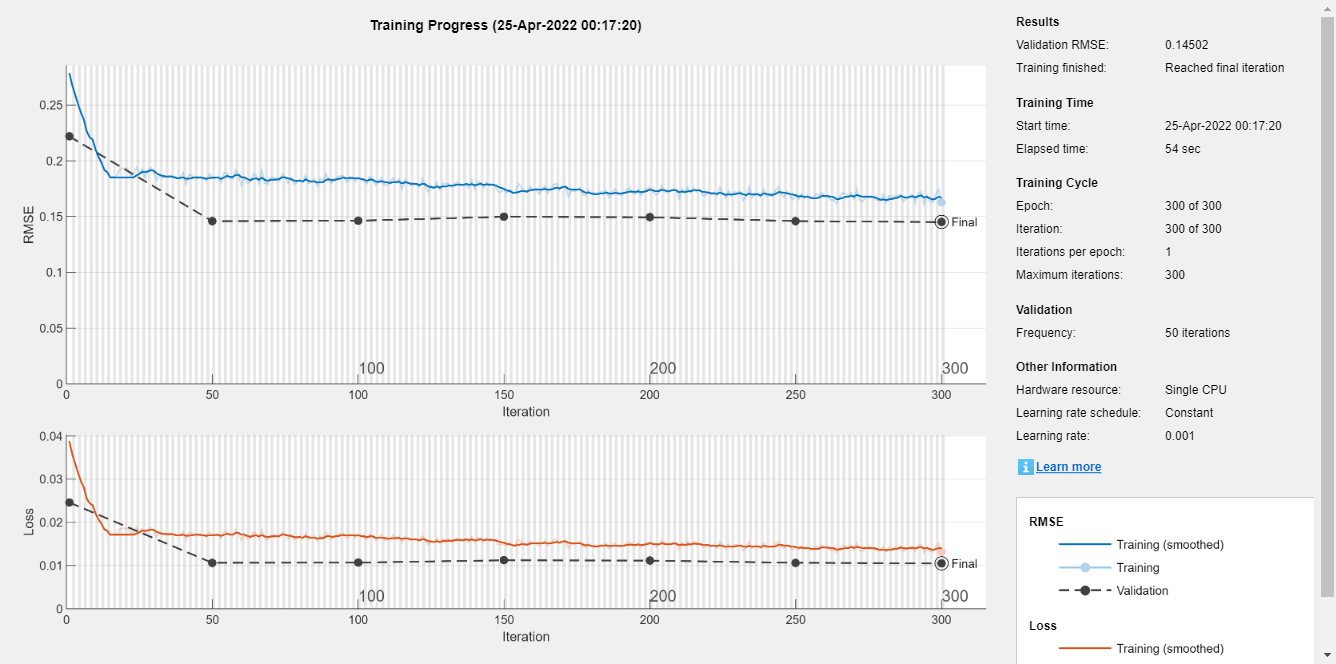

netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);


pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm(tr.testInd, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm(tr.testInd, :)', 1)));
ytest = ynorm(tr.testInd, :)*yrate + ymin;
pLSTM_hat = pLSTM * yrate + ymin;
pLSTM2_hat = pLSTM2 * yrate + ymin;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
238.1224

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
238.1224

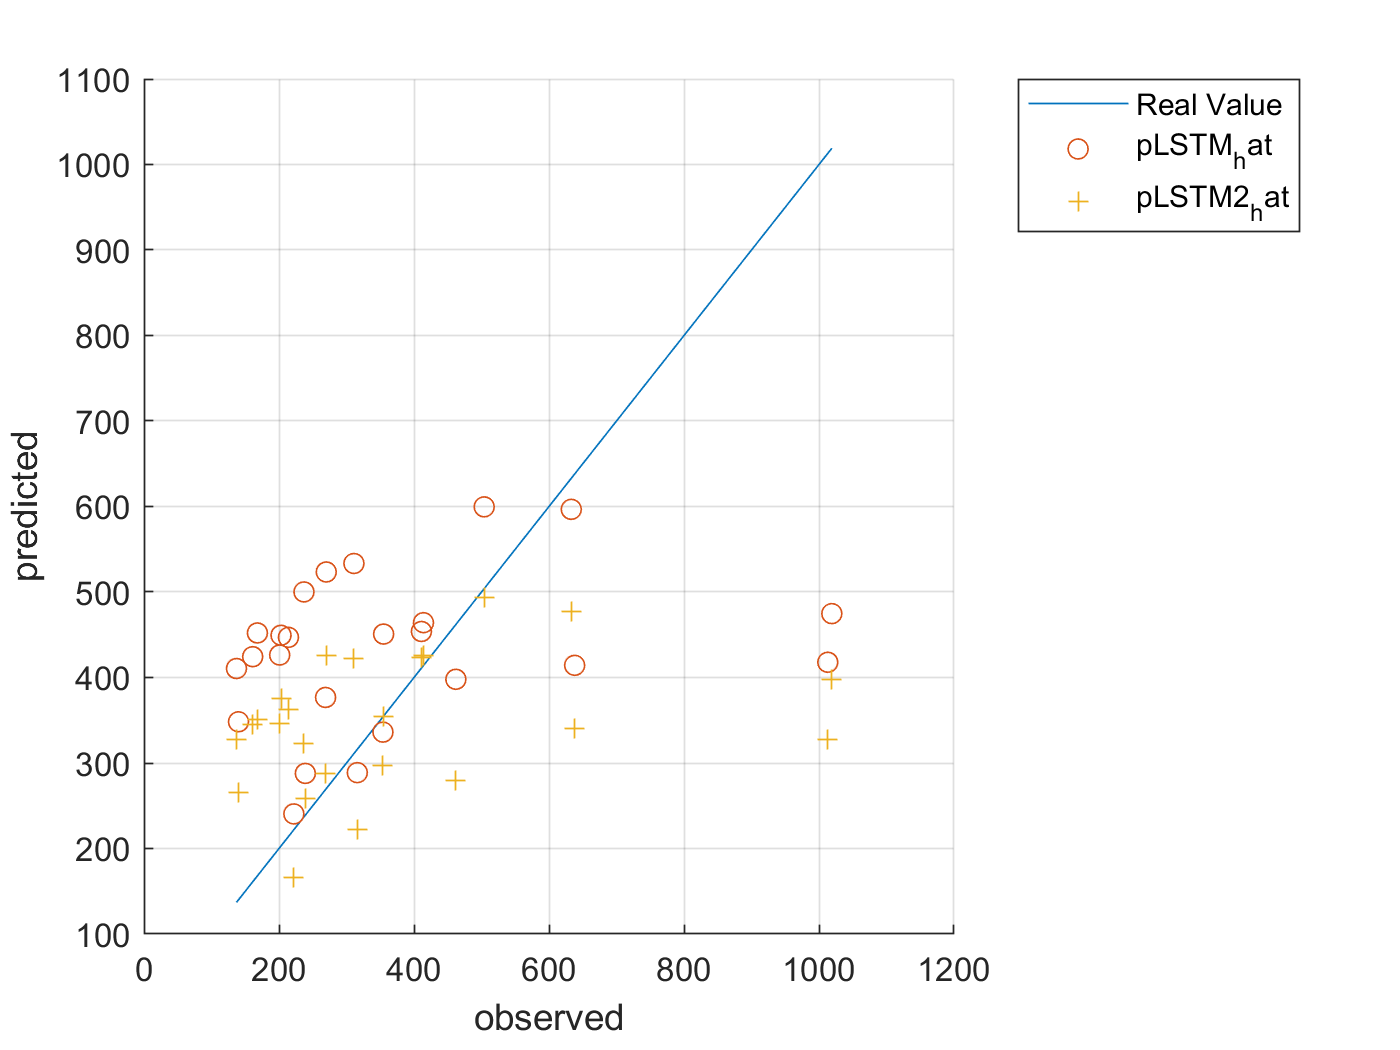



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')


save('ryan3_model_1stCC_cyclelife_v1.mat','netLSTM' ,'-append')
save('ryan3_model_1stCC_cyclelife_v1.mat','netLSTM2' ,'-append')

pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pLSTM_self = pLSTM_self * yrate + ymin;
pLSTM2_self = pLSTM2_self * yrate + ymin;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
215.7721

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
205.4026

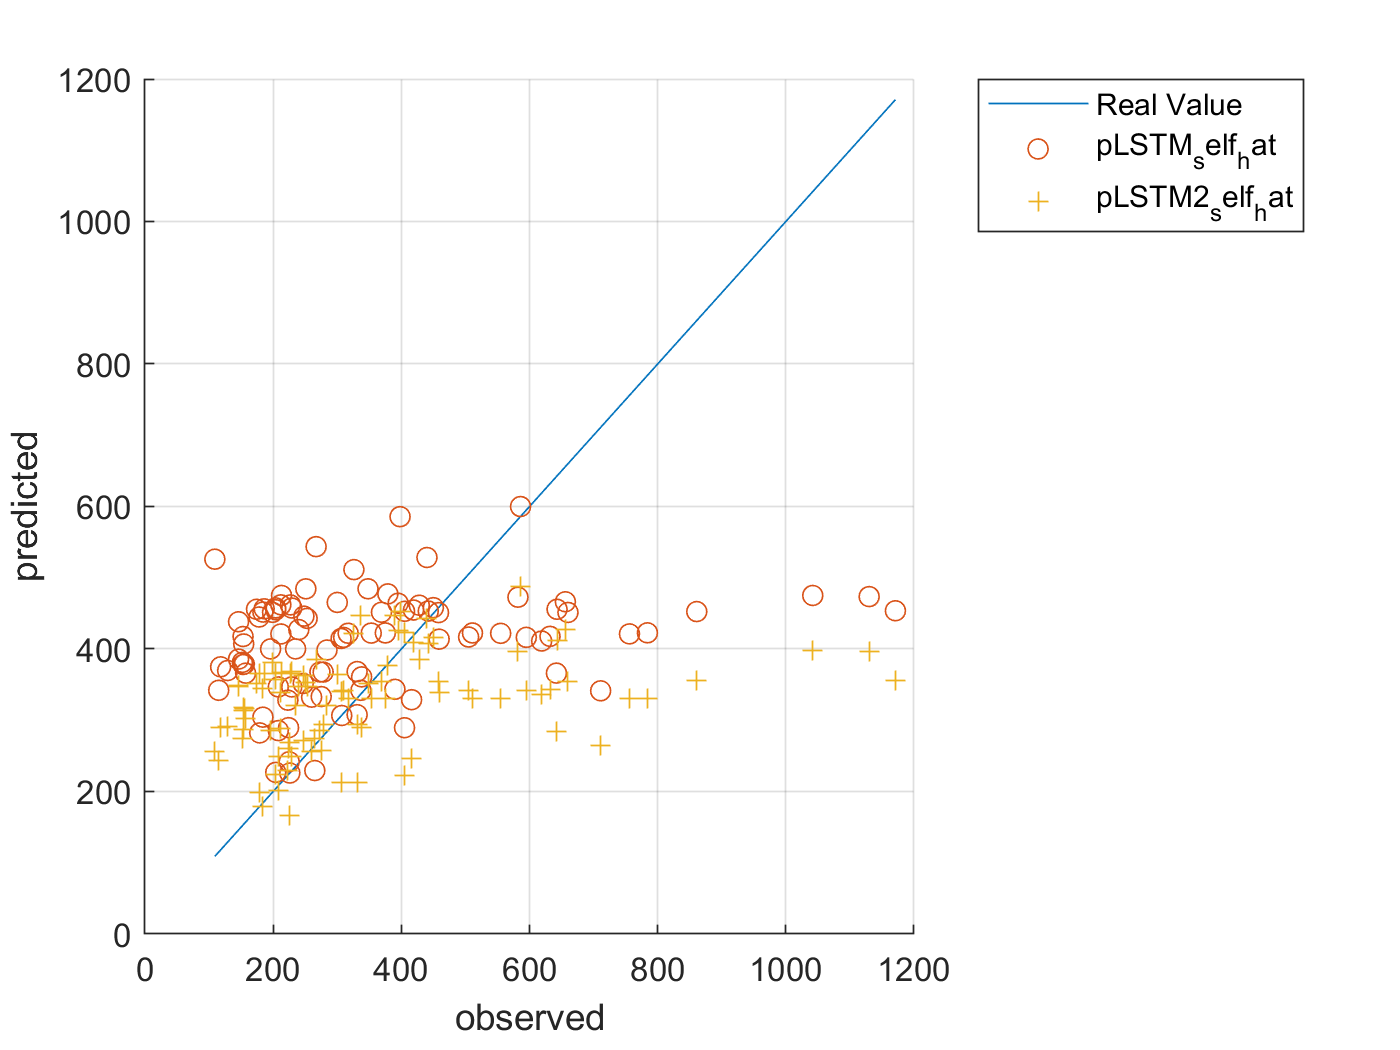


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')